# ME-8930 | LMIs for Robust & Optimal Control Design

## Capstone Project [Small Scale Vehicle - Nigel]

**Team:** Chinmay Samak and Tanmay Samak

clear;
close;
clc;

## System Modeling & Analysis

% System parameters

m = 2.68; % Mass [kg]
J = 0.01944; % Yaw moment of inertia [kg-m^2]
l = 0.1415; % Wheelbase [m]
l_f = 0.49*l; % Distance from CG to front axel [m]
l_r = l-l_f; % Distance from CG to rear axel [m]
C_fl = 2.4768; % Cornering stiffness of FL tire [N/rad]
C_fr = 2.4768; % Cornering stiffness of FR tire [N/rad]
C_rl = 2.4768; % Cornering stiffness of RL tire [N/rad]
C_rr = 2.4768; % Cornering stiffness of RR tire [N/rad]

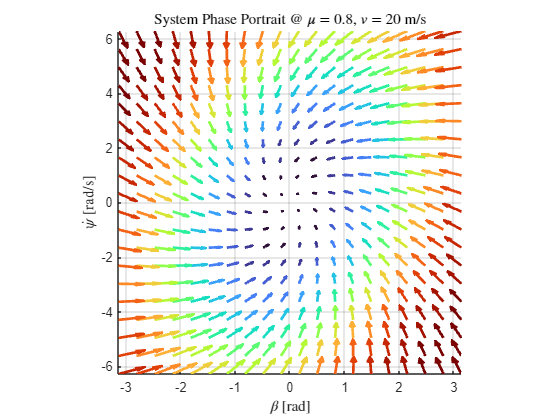

% System phase portrait

u_fl = 0.4; % Coefficient of friction for ground and FL tire interconnect
u_fr = 0.4; % Coefficient of friction for ground and FR tire interconnect
u_rl = 0.4; % Coefficient of friction for ground and RL tire interconnect
u_rr = 0.4; % Coefficient of friction for ground and RR tire interconnect
v = 0.35; % Vehicle velocity [m/s]

% Compute system matrix
a11 = -(1/(m*v)) * (u_fl*C_fl+u_fr*C_fr+u_rl*C_rl+u_rr*C_rr);
a12 = ((1/(m*v^2)) * (l_r*(u_rl*C_rl+u_rr*C_rr) - l_f*(u_fl*C_fl+u_fr*C_fr))) - 1;
a21 = (1/J) * (l_r*(u_rl*C_rl+u_rr*C_rr) - l_f*(u_fl*C_fl+u_fr*C_fr));
a22 = -(1/(J*v)) * (l_f^2*(u_fl*C_fl+u_fr*C_fr) + l_r^2*(u_rl*C_rl+u_rr*C_rr));
A = [a11 a12;
     a21 a22];

% Define a range of initial conditions
X1_range = linspace(-3.14159, 3.14159, 20);
X2_range = linspace(-6.28319, 6.28319, 20);

% Create a meshgrid of initial conditions
[X1, X2] = meshgrid(X1_range, X2_range);

% Initialize vectors to store the derivatives
X1_dot = zeros(size(X1));
X2_dot = zeros(size(X2));

% Calculate the derivatives for each initial condition
for i = 1:numel(X1)
    X_dot = A * [X1(i); X2(i)];
    X1_dot(i) = X_dot(1);
    X2_dot(i) = X_dot(2);
end
Z = (sqrt(X1_dot.^2 + X2_dot.^2));
Z = Z/max(Z,[],'all');
Z = reshape(Z.',1,[]);
[sortedZ, sortedIdx] = sort(Z);
sortedIdx = reshape(sortedIdx,[20,20]).';
X1_s = X1(sortedIdx);
X2_s = X2(sortedIdx);
X1_dot_s = X1_dot(sortedIdx);
X2_dot_s = X2_dot(sortedIdx);

% Plot
fig = figure(); 
fig.Position(3:4) = [560, 420];
cmap = turbo(size(X1_s,1)); 
hold on;
for i = 1:size(X1_s,1)
    quiver(X1_s(i,:),X2_s(i,:),X1_dot_s(i,:),X2_dot_s(i,:), .2, 'Color', cmap(i,:), 'LineWidth',2)
end
hold off;
xlabel('X1');
ylabel('X2');
xlabel('$\beta$ [rad]','Interpreter','latex');
ylabel('$\dot{\psi}$ [rad/s]','Interpreter','latex');
title('System Phase Portrait @ $\mu = 0.4$, $v = 0.35$ m/s','Interpreter','latex');
grid on;
axis tight;
pbaspect([1 1 1])

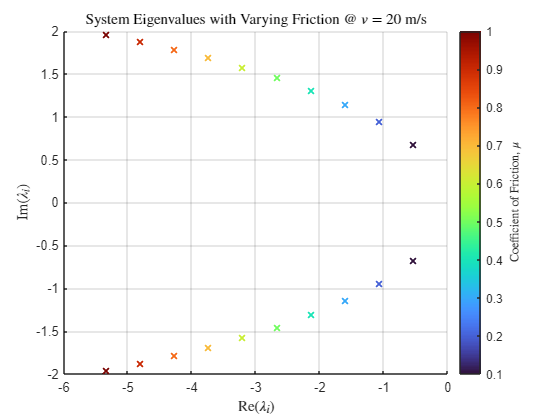

% System eignvalues with varying friction

EV = []; % Array to store system eigenvalues
v = 0.35; % Vehicle velocity [m/s]
for u=0.1:0.1:1
    % Set friction value
    u_fl = u;
    u_fr = u;
    u_rl = u;
    u_rr = u;
    % Update system matrix
    a11 = -(1/(m*v)) * (u_fl*C_fl+u_fr*C_fr+u_rl*C_rl+u_rr*C_rr);
    a12 = ((1/(m*v^2)) * (l_r*(u_rl*C_rl+u_rr*C_rr) - l_f*(u_fl*C_fl+u_fr*C_fr))) - 1;
    a21 = (1/J) * (l_r*(u_rl*C_rl+u_rr*C_rr) - l_f*(u_fl*C_fl+u_fr*C_fr));
    a22 = -(1/(J*v)) * (l_f^2*(u_fl*C_fl+u_fr*C_fr) + l_r^2*(u_rl*C_rl+u_rr*C_rr));
    A = [a11 a12;
         a21 a22];
    % Compute eigenvalues
    EV(:,end+1) = eig(A);
end

% Plot
u=0.1:0.1:1;
fig = figure(); 
fig.Position(3:4) = [560, 420];
scatter(real(EV(1,:)),imag(EV(1,:)),[],u,'LineWidth',1.5,'Marker','x')
hold on;
scatter(real(EV(2,:)),imag(EV(2,:)),[],u,'LineWidth',1.5,'Marker','x')
cb = colorbar();
ylabel(cb,'Coefficient of Friction, $\mu$','Interpreter','latex');
colormap turbo;
hold off;
xlabel('Re$(\lambda_i)$','Interpreter','latex');
ylabel('Im$(\lambda_i)$','Interpreter','latex');
title('System Eigenvalues with Varying Friction @ $v = 0.35$ m/s','Interpreter','latex');
grid on;

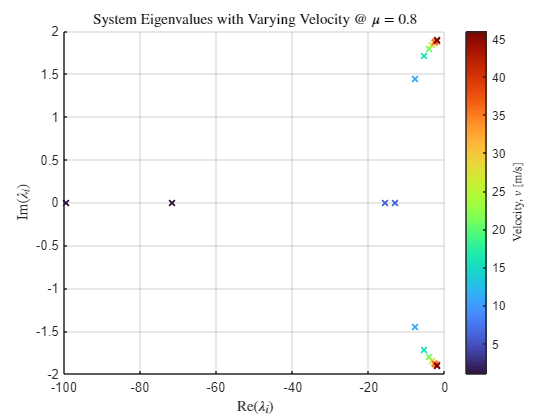

% System eignvalues with varying velocity

EV = []; % Array to store system eigenvalues
u = 0.4; % Coefficient of friction for ground and tire interconnect
for v=1:0.035:0.35
    % Set friction value
    u_fl = u;
    u_fr = u;
    u_rl = u;
    u_rr = u;
    % Update system matrix
    a11 = -(1/(m*v)) * (u_fl*C_fl+u_fr*C_fr+u_rl*C_rl+u_rr*C_rr);
    a12 = ((1/(m*v^2)) * (l_r*(u_rl*C_rl+u_rr*C_rr) - l_f*(u_fl*C_fl+u_fr*C_fr))) - 1;
    a21 = (1/J) * (l_r*(u_rl*C_rl+u_rr*C_rr) - l_f*(u_fl*C_fl+u_fr*C_fr));
    a22 = -(1/(J*v)) * (l_f^2*(u_fl*C_fl+u_fr*C_fr) + l_r^2*(u_rl*C_rl+u_rr*C_rr));
    A = [a11 a12;
         a21 a22];
    % Compute eigenvalues
    EV(:,end+1) = eig(A);
end

% Plot
v=1:0.035:0.35;
fig = figure(); 
fig.Position(3:4) = [560, 420];
scatter(real(EV(1,:)),imag(EV(1,:)),[],v,'LineWidth',1.5,'Marker','x')
hold on;
scatter(real(EV(2,:)),imag(EV(2,:)),[],v,'LineWidth',1.5,'Marker','x')
cb = colorbar();
ylabel(cb,'Velocity, $v$ [m/s]','Interpreter','latex');
colormap turbo;
hold off;
xlabel('Re$(\lambda_i)$','Interpreter','latex');
ylabel('Im$(\lambda_i)$','Interpreter','latex');
title('System Eigenvalues with Varying Velocity @ $\mu = 0.4$','Interpreter','latex');
grid on;

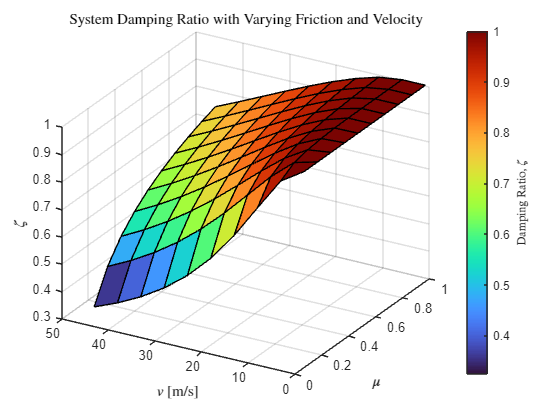

% System damping ratio with varying friction and velocity

zeta = []; % Array to store system eigenvalues
for u=0.1:0.1:1
    for v=1:0.035:0.35
        % Set friction value
        u_fl = u;
        u_fr = u;
        u_rl = u;
        u_rr = u;
        % Update system matrix
        a11 = -(1/(m*v)) * (u_fl*C_fl+u_fr*C_fr+u_rl*C_rl+u_rr*C_rr);
        a12 = ((1/(m*v^2)) * (l_r*(u_rl*C_rl+u_rr*C_rr) - l_f*(u_fl*C_fl+u_fr*C_fr))) - 1;
        a21 = (1/J) * (l_r*(u_rl*C_rl+u_rr*C_rr) - l_f*(u_fl*C_fl+u_fr*C_fr));
        a22 = -(1/(J*v)) * (l_f^2*(u_fl*C_fl+u_fr*C_fr) + l_r^2*(u_rl*C_rl+u_rr*C_rr));
        A = [a11 a12;
             a21 a22];
        % Compute damping ratio
        EV = eig(A);
        zeta(:,end+1) = -real(EV)./abs(EV);
    end
end

% Plot
u=0.1:0.1:1;
v=1:0.035:0.35;
[X,Y] = meshgrid(u,v);
Z = reshape(zeta(1, :), 10, 10);
fig = figure(); 
fig.Position(3:4) = [560, 420];
s = surf(X,Y,Z,'FaceAlpha',1.0);
hold on;
cb = colorbar();
ylabel(cb,'Damping Ratio, $\zeta$','Interpreter','latex');
colormap turbo;
hold off;
xlabel('$\mu$','Interpreter','latex');
ylabel('$v$ [m/s]','Interpreter','latex');
zlabel('$\zeta$','Interpreter','latex');
title('System Damping Ratio with Varying Friction and Velocity','Interpreter','latex');
grid on;
view([-60 30]);

## Model Simulation for Benckmark Maneuvers with Varying Friction

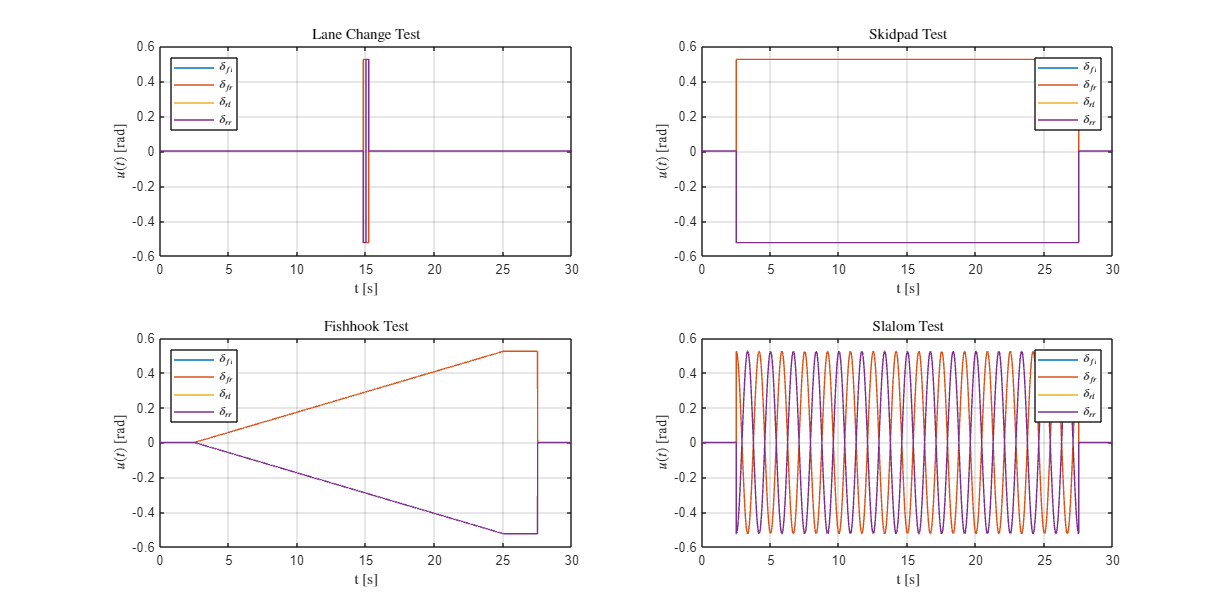

% Maneuver parameters

% Lane change test (impulse input)
u1_lane_change = [ones(1,14800)*(deg2rad(0)) ones(1,200)*(deg2rad(30)) ones(1,200)*(deg2rad(-30)) ones(1,14800)*(deg2rad(0))];
u2_lane_change = [ones(1,14800)*(deg2rad(0)) ones(1,200)*(deg2rad(30)) ones(1,200)*(deg2rad(-30)) ones(1,14800)*(deg2rad(0))];
u3_lane_change = [ones(1,14800)*(deg2rad(0)) ones(1,200)*(deg2rad(-30)) ones(1,200)*(deg2rad(30)) ones(1,14800)*(deg2rad(0))];
u4_lane_change = [ones(1,14800)*(deg2rad(0)) ones(1,200)*(deg2rad(-30)) ones(1,200)*(deg2rad(30)) ones(1,14800)*(deg2rad(0))];
u_lane_change = [u1_lane_change; u2_lane_change; u3_lane_change; u4_lane_change];
w_lane_change = zeros(1,30000);

% Skidpad test (step input)
u1_skidpad = [ones(1,2500)*(deg2rad(0)) ones(1,25000)*(deg2rad(30)) ones(1,2500)*(deg2rad(0))];
u2_skidpad = [ones(1,2500)*(deg2rad(0)) ones(1,25000)*(deg2rad(30)) ones(1,2500)*(deg2rad(0))];
u3_skidpad = [ones(1,2500)*(deg2rad(0)) ones(1,25000)*(deg2rad(-30)) ones(1,2500)*(deg2rad(0))];
u4_skidpad = [ones(1,2500)*(deg2rad(0)) ones(1,25000)*(deg2rad(-30)) ones(1,2500)*(deg2rad(0))];
u_skidpad = [u1_skidpad; u2_skidpad; u3_skidpad; u4_skidpad];
w_skidpad = zeros(1,30000);

% Fishhook test (ramp input)
angles = deg2rad(linspace(0,30,22500));
u1_fishhook = [ones(1,2500)*(deg2rad(0)) angles ones(1,2500)*deg2rad(30) ones(1,2500)*(deg2rad(0))];
u2_fishhook = [ones(1,2500)*(deg2rad(0)) angles ones(1,2500)*deg2rad(30) ones(1,2500)*(deg2rad(0))];
u3_fishhook = [ones(1,2500)*(deg2rad(0)) -angles ones(1,2500)*deg2rad(-30) ones(1,2500)*(deg2rad(0))];
u4_fishhook = [ones(1,2500)*(deg2rad(0)) -angles ones(1,2500)*deg2rad(-30) ones(1,2500)*(deg2rad(0))];
u_fishhook = [u1_fishhook; u2_fishhook; u3_fishhook; u4_fishhook];
w_fishhook = zeros(1,30000);

% Slalom test (sine input)
n_cones = 30;
angles = linspace(0,n_cones*pi,25000);
u1_slalom = [ones(1,2500)*(deg2rad(0)) deg2rad(30*cos(angles)) ones(1,2500)*(deg2rad(0))];
u2_slalom = [ones(1,2500)*(deg2rad(0)) deg2rad(30*cos(angles)) ones(1,2500)*(deg2rad(0))];
u3_slalom = [ones(1,2500)*(deg2rad(0)) deg2rad(-30*cos(angles)) ones(1,2500)*(deg2rad(0))];
u4_slalom = [ones(1,2500)*(deg2rad(0)) deg2rad(-30*cos(angles)) ones(1,2500)*(deg2rad(0))];
u_slalom = [u1_slalom; u2_slalom; u3_slalom; u4_slalom];
w_slalom = zeros(1,30000);

% Plot
t=1:30000;
fig = figure(); 
fig.Position(3:4) = [4000, 2000];
% Lane change (impulse)
subplot(2,2,1)
plot(t/1000,u1_lane_change)
hold on;
plot(t/1000,u2_lane_change)
plot(t/1000,u3_lane_change)
plot(t/1000,u4_lane_change)
legend('$\delta_{fl}$','$\delta_{fr}$','$\delta_{rl}$','$\delta_{rr}$','Interpreter','latex','Location','northwest')
xlabel('t [s]','Interpreter','latex')
ylabel('$u(t)$ [rad]','Interpreter','latex')
title('Lane Change Test','Interpreter','latex')
grid on;
hold off;
% Skidpad (step)
subplot(2,2,2)
plot(t/1000,u1_skidpad)
hold on;
plot(t/1000,u2_skidpad)
plot(t/1000,u3_skidpad)
plot(t/1000,u4_skidpad)
legend('$\delta_{fl}$','$\delta_{fr}$','$\delta_{rl}$','$\delta_{rr}$','Interpreter','latex','Location','northeast')
xlabel('t [s]','Interpreter','latex')
ylabel('$u(t)$ [rad]','Interpreter','latex')
title('Skidpad Test','Interpreter','latex')
grid on;
hold off;
% Fishhook (ramp)
subplot(2,2,3)
plot(t/1000,u1_fishhook)
hold on;
plot(t/1000,u2_fishhook)
plot(t/1000,u3_fishhook)
plot(t/1000,u4_fishhook)
legend('$\delta_{fl}$','$\delta_{fr}$','$\delta_{rl}$','$\delta_{rr}$','Interpreter','latex','Location','northwest')
xlabel('t [s]','Interpreter','latex')
ylabel('$u(t)$ [rad]','Interpreter','latex')
title('Fishhook Test','Interpreter','latex')
grid on;
hold off;
% Slalom (sine)
subplot(2,2,4)
plot(t/1000,u1_slalom)
hold on;
plot(t/1000,u2_slalom)
plot(t/1000,u3_slalom)
plot(t/1000,u4_slalom)
legend('$\delta_{fl}$','$\delta_{fr}$','$\delta_{rl}$','$\delta_{rr}$','Interpreter','latex','Location','northeast')
xlabel('t [s]','Interpreter','latex')
ylabel('$u(t)$ [rad]','Interpreter','latex')
title('Slalom Test','Interpreter','latex')
grid on;
hold off;

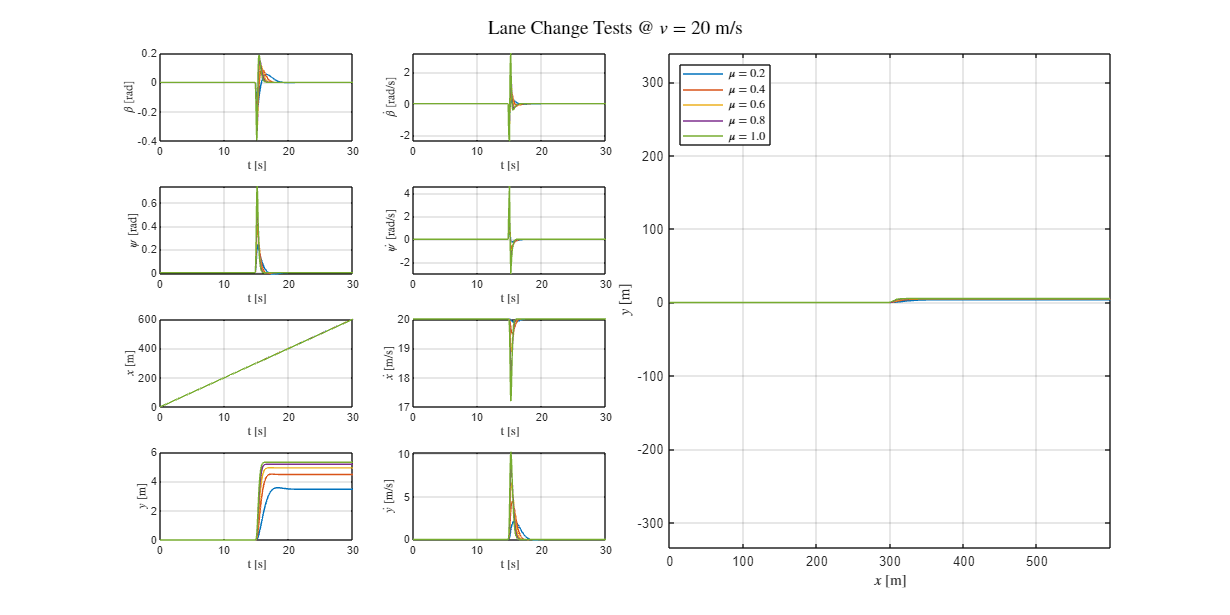

% Simulate lane change tests with varying friction

BETA_LC = [];
BETA_DOT_LC = [];
PSI_LC = [];
PSI_DOT_LC = [];
PX_LC = [];
VX_LC = [];
PY_LC = [];
VY_LC = [];

for u=0.2:0.2:1

    % Initialization
    dt = 0.001; % Simulation timestep [s]
    v = 0.35; % Vehicle velocity [m/s]
    X = [];
    X(:,1) = [0;0];
    X_dot = [];
    Psi = [];
    Psi(1) = 0;
    Beta = [];
    Vx = [];
    Vy = [];
    Px = [];
    Px(1) = 0;
    Py = [];
    Py(1) = 0;

    % Set friction value
    u_fl = u;
    u_fr = u;
    u_rl = u;
    u_rr = u;

    % Update system matrix
    a11 = -(1/(m*v)) * (u_fl*C_fl+u_fr*C_fr+u_rl*C_rl+u_rr*C_rr);
    a12 = ((1/(m*v^2)) * (l_r*(u_rl*C_rl+u_rr*C_rr) - l_f*(u_fl*C_fl+u_fr*C_fr))) - 1;
    a21 = (1/J) * (l_r*(u_rl*C_rl+u_rr*C_rr) - l_f*(u_fl*C_fl+u_fr*C_fr));
    a22 = -(1/(J*v)) * (l_f^2*(u_fl*C_fl+u_fr*C_fr) + l_r^2*(u_rl*C_rl+u_rr*C_rr));
    A = [a11 a12;
         a21 a22];

    % Update control input matrix
    b11 = (u_fl*C_fl)/(m*v);
    b12 = (u_fr*C_fr)/(m*v);
    b13 = (u_rl*C_rl)/(m*v);
    b14 = (u_rr*C_rr)/(m*v);
    b21 = (l_f*u_fl*C_fl)/J;
    b22 = (l_f*u_fr*C_fr)/J;
    b23 = -(l_r*u_rl*C_rl)/J;
    b24 = -(l_r*u_rr*C_rr)/J;
    B = [b11 b12 b13 b14;
         b21 b22 b23 b24];
    
    % Update disturbance input matrix
    B_d = [1/(m*v);
           (l_f-l_r)/2];
    
    % Simulation at each millisecond
    for t=1:30000
        X_dot(:,t) = A*X(:,t) + B*u_lane_change(:,t) + B_d*(w_lane_change(:,t).*cos(Psi(t)));
        X(:,t+1) = X(:,t) + X_dot(:,t)*dt;
        Beta(t) = X(1,t);
        Psi(t+1) = Psi(t) + X(2,t)*dt;
        Vx(t) = v*cos(Psi(t) + Beta(t));
        Vy(t) = v*sin(Psi(t) + Beta(t));
        Px(t+1) = Px(t) + Vx(t)*dt;
        Py(t+1) = Py(t) + Vy(t)*dt;
    end
    BETA_LC(end+1,:) = Beta;
    BETA_DOT_LC(end+1,:) = X_dot(1,:);
    PSI_LC(end+1,:) = Psi;
    PSI_DOT_LC(end+1,:) = X(2,:);
    PX_LC(end+1,:) = Px;
    VX_LC(end+1,:) = Vx;
    PY_LC(end+1,:) = Py;
    VY_LC(end+1,:) = Vy;
end

% Plot
t=1:30000;
u=0.2:0.2:1;
fig = figure(); 
fig.Position(3:4) = [1500, 750];
% Plot states
subplot(4,4,1)
plot(t/1000,BETA_LC(:,1:end)')
xlabel('t [s]','Interpreter','latex')
ylabel('$\beta$ [rad]','Interpreter','latex')
grid('on')
subplot(4,4,2)
plot(t/1000,BETA_DOT_LC(:,1:end)')
xlabel('t [s]','Interpreter','latex')
ylabel('$\dot{\beta}$ [rad/s]','Interpreter','latex')
grid('on')
subplot(4,4,5)
plot(t/1000,PSI_LC(:,1:end-1)')
xlabel('t [s]','Interpreter','latex')
ylabel('$\psi$ [rad]','Interpreter','latex')
grid('on')
subplot(4,4,6)
plot(t/1000,PSI_DOT_LC(:,1:end-1)')
xlabel('t [s]','Interpreter','latex')
ylabel('$\dot{\psi}$ [rad/s]','Interpreter','latex')
grid('on')
subplot(4,4,9)
plot(t/1000,PX_LC(:,1:end-1)')
xlabel('t [s]','Interpreter','latex')
ylabel('$x$ [m]','Interpreter','latex')
grid('on')
subplot(4,4,10)
plot(t/1000,VX_LC(:,1:end)')
xlabel('t [s]','Interpreter','latex')
ylabel('$\dot{x}$ [m/s]','Interpreter','latex')
grid('on')
subplot(4,4,13)
plot(t/1000,PY_LC(:,1:end-1)')
xlabel('t [s]','Interpreter','latex')
ylabel('$y$ [m]','Interpreter','latex')
grid('on')
subplot(4,4,14)
plot(t/1000,VY_LC(:,1:end)')
xlabel('t [s]','Interpreter','latex')
ylabel('$\dot{y}$ [m/s]','Interpreter','latex')
grid('on')
% Plot trajectory
subplot(4,4,[3,4,7,8,11,12,15,16])
plot(PX_LC(:,1:end-1)',PY_LC(:,1:end-1)')
xlabel('$x$ [m]','Interpreter','latex')
ylabel('$y$ [m]','Interpreter','latex')
axis equal
grid('on')
% Common title and legend
sgtitle('Lane Change Tests @ $v = 0.35$ m/s','Interpreter','latex')
legend('$\mu = 0.2$','$\mu = 0.4$','$\mu = 0.6$','$\mu = 0.8$','$\mu = 1.0$', ...
       'Interpreter','latex','Location','northwest')

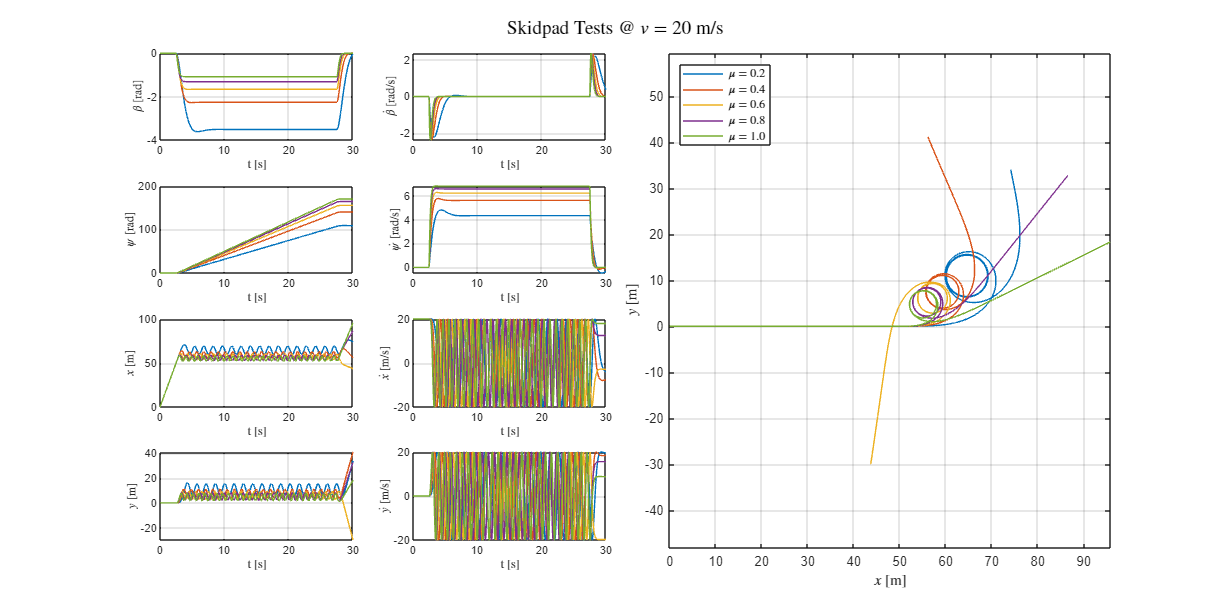

% Simulate skidpad tests with varying friction

BETA_SP = [];
BETA_DOT_SP = [];
PSI_SP = [];
PSI_DOT_SP = [];
PX_SP = [];
VX_SP = [];
PY_SP = [];
VY_SP = [];

for u=0.2:0.2:1

    % Initialization
    dt = 0.001; % Simulation timestep [s]
    v = 0.35; % Vehicle velocity [m/s]
    X = [];
    X(:,1) = [0;0];
    X_dot = [];
    Psi = [];
    Psi(1) = 0;
    Beta = [];
    Vx = [];
    Vy = [];
    Px = [];
    Px(1) = 0;
    Py = [];
    Py(1) = 0;

    % Set friction value
    u_fl = u;
    u_fr = u;
    u_rl = u;
    u_rr = u;

    % Update system matrix
    a11 = -(1/(m*v)) * (u_fl*C_fl+u_fr*C_fr+u_rl*C_rl+u_rr*C_rr);
    a12 = ((1/(m*v^2)) * (l_r*(u_rl*C_rl+u_rr*C_rr) - l_f*(u_fl*C_fl+u_fr*C_fr))) - 1;
    a21 = (1/J) * (l_r*(u_rl*C_rl+u_rr*C_rr) - l_f*(u_fl*C_fl+u_fr*C_fr));
    a22 = -(1/(J*v)) * (l_f^2*(u_fl*C_fl+u_fr*C_fr) + l_r^2*(u_rl*C_rl+u_rr*C_rr));
    A = [a11 a12;
         a21 a22];

    % Update control input matrix
    b11 = (u_fl*C_fl)/(m*v);
    b12 = (u_fr*C_fr)/(m*v);
    b13 = (u_rl*C_rl)/(m*v);
    b14 = (u_rr*C_rr)/(m*v);
    b21 = (l_f*u_fl*C_fl)/J;
    b22 = (l_f*u_fr*C_fr)/J;
    b23 = -(l_r*u_rl*C_rl)/J;
    b24 = -(l_r*u_rr*C_rr)/J;
    B = [b11 b12 b13 b14;
         b21 b22 b23 b24];
    
    % Update disturbance input matrix
    B_d = [1/(m*v);
           (l_f-l_r)/2];
    
    % Simulation at each millisecond
    for t=1:30000
        X_dot(:,t) = A*X(:,t) + B*u_skidpad(:,t) + B_d*(w_skidpad(:,t).*cos(Psi(t)));
        X(:,t+1) = X(:,t) + X_dot(:,t)*dt;
        Beta(t) = X(1,t);
        Psi(t+1) = Psi(t) + X(2,t)*dt;
        Vx(t) = v*cos(Psi(t) + Beta(t));
        Vy(t) = v*sin(Psi(t) + Beta(t));
        Px(t+1) = Px(t) + Vx(t)*dt;
        Py(t+1) = Py(t) + Vy(t)*dt;
    end
    BETA_SP(end+1,:) = Beta;
    BETA_DOT_SP(end+1,:) = X_dot(1,:);
    PSI_SP(end+1,:) = Psi;
    PSI_DOT_SP(end+1,:) = X(2,:);
    PX_SP(end+1,:) = Px;
    VX_SP(end+1,:) = Vx;
    PY_SP(end+1,:) = Py;
    VY_SP(end+1,:) = Vy;
end

% Plot
t=1:30000;
u=0.2:0.2:1;
fig = figure(); 
fig.Position(3:4) = [1500, 750];
% Plot states
subplot(4,4,1)
plot(t/1000,BETA_SP(:,1:end)')
xlabel('t [s]','Interpreter','latex')
ylabel('$\beta$ [rad]','Interpreter','latex')
grid('on')
subplot(4,4,2)
plot(t/1000,BETA_DOT_SP(:,1:end)')
xlabel('t [s]','Interpreter','latex')
ylabel('$\dot{\beta}$ [rad/s]','Interpreter','latex')
grid('on')
subplot(4,4,5)
plot(t/1000,PSI_SP(:,1:end-1)')
xlabel('t [s]','Interpreter','latex')
ylabel('$\psi$ [rad]','Interpreter','latex')
grid('on')
subplot(4,4,6)
plot(t/1000,PSI_DOT_SP(:,1:end-1)')
xlabel('t [s]','Interpreter','latex')
ylabel('$\dot{\psi}$ [rad/s]','Interpreter','latex')
grid('on')
subplot(4,4,9)
plot(t/1000,PX_SP(:,1:end-1)')
xlabel('t [s]','Interpreter','latex')
ylabel('$x$ [m]','Interpreter','latex')
grid('on')
subplot(4,4,10)
plot(t/1000,VX_SP(:,1:end)')
xlabel('t [s]','Interpreter','latex')
ylabel('$\dot{x}$ [m/s]','Interpreter','latex')
grid('on')
subplot(4,4,13)
plot(t/1000,PY_SP(:,1:end-1)')
xlabel('t [s]','Interpreter','latex')
ylabel('$y$ [m]','Interpreter','latex')
grid('on')
subplot(4,4,14)
plot(t/1000,VY_SP(:,1:end)')
xlabel('t [s]','Interpreter','latex')
ylabel('$\dot{y}$ [m/s]','Interpreter','latex')
grid('on')
% Plot trajectory
subplot(4,4,[3,4,7,8,11,12,15,16])
plot(PX_SP(:,1:end-1)',PY_SP(:,1:end-1)')
xlabel('$x$ [m]','Interpreter','latex')
ylabel('$y$ [m]','Interpreter','latex')
axis equal
grid('on')
% Common title and legend
sgtitle('Skidpad Tests @ $v = 0.35$ m/s','Interpreter','latex')
legend('$\mu = 0.2$','$\mu = 0.4$','$\mu = 0.6$','$\mu = 0.8$','$\mu = 1.0$', ...
       'Interpreter','latex','Location','northwest')

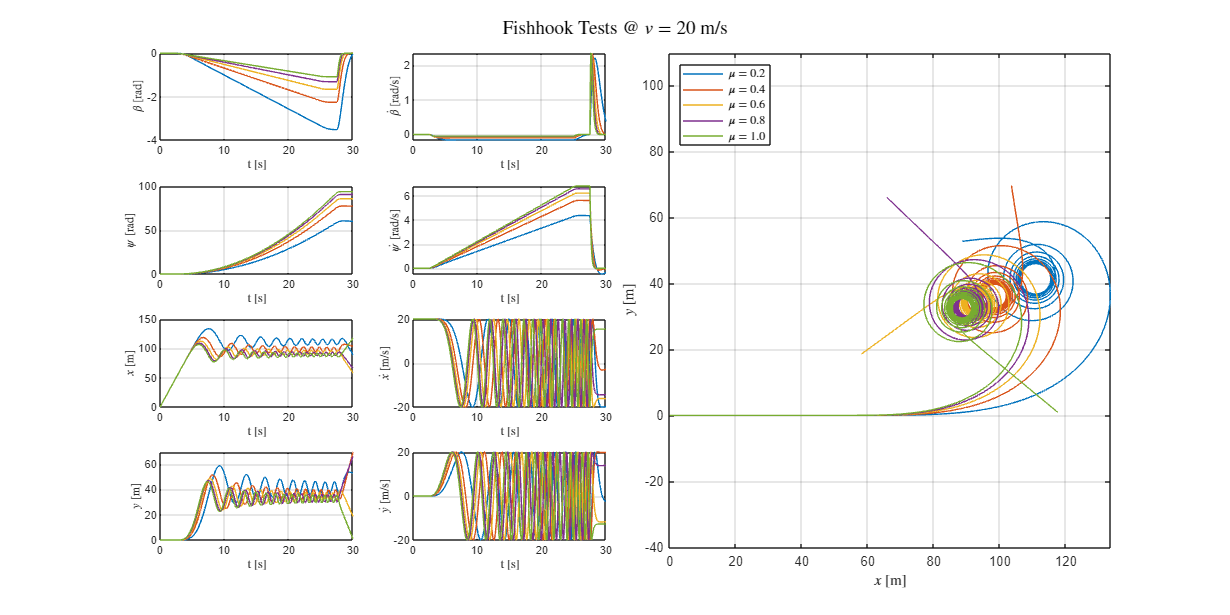

% Simulate fishhook tests with varying friction

BETA_FH = [];
BETA_DOT_FH = [];
PSI_FH = [];
PSI_DOT_FH = [];
PX_FH = [];
VX_FH = [];
PY_FH = [];
VY_FH = [];

for u=0.2:0.2:1

    % Initialization
    dt = 0.001; % Simulation timestep [s]
    v = 0.35; % Vehicle velocity [m/s]
    X = [];
    X(:,1) = [0;0];
    X_dot = [];
    Psi = [];
    Psi(1) = 0;
    Beta = [];
    Vx = [];
    Vy = [];
    Px = [];
    Px(1) = 0;
    Py = [];
    Py(1) = 0;

    % Set friction value
    u_fl = u;
    u_fr = u;
    u_rl = u;
    u_rr = u;

    % Update system matrix
    a11 = -(1/(m*v)) * (u_fl*C_fl+u_fr*C_fr+u_rl*C_rl+u_rr*C_rr);
    a12 = ((1/(m*v^2)) * (l_r*(u_rl*C_rl+u_rr*C_rr) - l_f*(u_fl*C_fl+u_fr*C_fr))) - 1;
    a21 = (1/J) * (l_r*(u_rl*C_rl+u_rr*C_rr) - l_f*(u_fl*C_fl+u_fr*C_fr));
    a22 = -(1/(J*v)) * (l_f^2*(u_fl*C_fl+u_fr*C_fr) + l_r^2*(u_rl*C_rl+u_rr*C_rr));
    A = [a11 a12;
         a21 a22];

    % Update control input matrix
    b11 = (u_fl*C_fl)/(m*v);
    b12 = (u_fr*C_fr)/(m*v);
    b13 = (u_rl*C_rl)/(m*v);
    b14 = (u_rr*C_rr)/(m*v);
    b21 = (l_f*u_fl*C_fl)/J;
    b22 = (l_f*u_fr*C_fr)/J;
    b23 = -(l_r*u_rl*C_rl)/J;
    b24 = -(l_r*u_rr*C_rr)/J;
    B = [b11 b12 b13 b14;
         b21 b22 b23 b24];
    
    % Update disturbance input matrix
    B_d = [1/(m*v);
           (l_f-l_r)/2];
    
    % Simulation at each millisecond
    for t=1:30000
        X_dot(:,t) = A*X(:,t) + B*u_fishhook(:,t) + B_d*(w_fishhook(:,t).*cos(Psi(t)));
        X(:,t+1) = X(:,t) + X_dot(:,t)*dt;
        Beta(t) = X(1,t);
        Psi(t+1) = Psi(t) + X(2,t)*dt;
        Vx(t) = v*cos(Psi(t) + Beta(t));
        Vy(t) = v*sin(Psi(t) + Beta(t));
        Px(t+1) = Px(t) + Vx(t)*dt;
        Py(t+1) = Py(t) + Vy(t)*dt;
    end
    BETA_FH(end+1,:) = Beta;
    BETA_DOT_FH(end+1,:) = X_dot(1,:);
    PSI_FH(end+1,:) = Psi;
    PSI_DOT_FH(end+1,:) = X(2,:);
    PX_FH(end+1,:) = Px;
    VX_FH(end+1,:) = Vx;
    PY_FH(end+1,:) = Py;
    VY_FH(end+1,:) = Vy;
end

% Plot
t=1:30000;
u=0.2:0.2:1;
fig = figure(); 
fig.Position(3:4) = [1500, 750];
% Plot states
subplot(4,4,1)
plot(t/1000,BETA_FH(:,1:end)')
xlabel('t [s]','Interpreter','latex')
ylabel('$\beta$ [rad]','Interpreter','latex')
grid('on')
subplot(4,4,2)
plot(t/1000,BETA_DOT_FH(:,1:end)')
xlabel('t [s]','Interpreter','latex')
ylabel('$\dot{\beta}$ [rad/s]','Interpreter','latex')
grid('on')
subplot(4,4,5)
plot(t/1000,PSI_FH(:,1:end-1)')
xlabel('t [s]','Interpreter','latex')
ylabel('$\psi$ [rad]','Interpreter','latex')
grid('on')
subplot(4,4,6)
plot(t/1000,PSI_DOT_FH(:,1:end-1)')
xlabel('t [s]','Interpreter','latex')
ylabel('$\dot{\psi}$ [rad/s]','Interpreter','latex')
grid('on')
subplot(4,4,9)
plot(t/1000,PX_FH(:,1:end-1)')
xlabel('t [s]','Interpreter','latex')
ylabel('$x$ [m]','Interpreter','latex')
grid('on')
subplot(4,4,10)
plot(t/1000,VX_FH(:,1:end)')
xlabel('t [s]','Interpreter','latex')
ylabel('$\dot{x}$ [m/s]','Interpreter','latex')
grid('on')
subplot(4,4,13)
plot(t/1000,PY_FH(:,1:end-1)')
xlabel('t [s]','Interpreter','latex')
ylabel('$y$ [m]','Interpreter','latex')
grid('on')
subplot(4,4,14)
plot(t/1000,VY_FH(:,1:end)')
xlabel('t [s]','Interpreter','latex')
ylabel('$\dot{y}$ [m/s]','Interpreter','latex')
grid('on')
% Plot trajectory
subplot(4,4,[3,4,7,8,11,12,15,16])
plot(PX_FH(:,1:end-1)',PY_FH(:,1:end-1)')
xlabel('$x$ [m]','Interpreter','latex')
ylabel('$y$ [m]','Interpreter','latex')
axis equal
grid('on')
% Common title and legend
sgtitle('Fishhook Tests @ $v = 0.35$ m/s','Interpreter','latex')
legend('$\mu = 0.2$','$\mu = 0.4$','$\mu = 0.6$','$\mu = 0.8$','$\mu = 1.0$', ...
       'Interpreter','latex','Location','northwest')

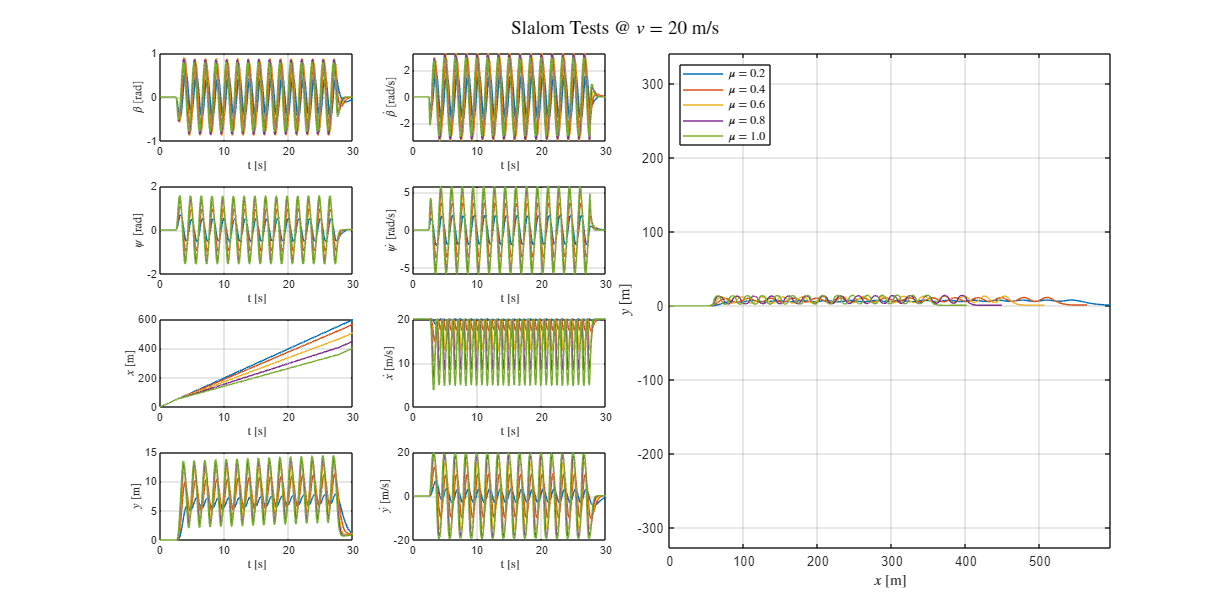

% Simulate slalom tests with varying friction

BETA_SL = [];
BETA_DOT_SL = [];
PSI_SL = [];
PSI_DOT_SL = [];
PX_SL = [];
VX_SL = [];
PY_SL = [];
VY_SL = [];

for u=0.2:0.2:1

    % Initialization
    dt = 0.001; % Simulation timestep [s]
    v = 0.35; % Vehicle velocity [m/s]
    X = [];
    X(:,1) = [0;0];
    X_dot = [];
    Psi = [];
    Psi(1) = 0;
    Beta = [];
    Vx = [];
    Vy = [];
    Px = [];
    Px(1) = 0;
    Py = [];
    Py(1) = 0;

    % Set friction value
    u_fl = u;
    u_fr = u;
    u_rl = u;
    u_rr = u;

    % Update system matrix
    a11 = -(1/(m*v)) * (u_fl*C_fl+u_fr*C_fr+u_rl*C_rl+u_rr*C_rr);
    a12 = ((1/(m*v^2)) * (l_r*(u_rl*C_rl+u_rr*C_rr) - l_f*(u_fl*C_fl+u_fr*C_fr))) - 1;
    a21 = (1/J) * (l_r*(u_rl*C_rl+u_rr*C_rr) - l_f*(u_fl*C_fl+u_fr*C_fr));
    a22 = -(1/(J*v)) * (l_f^2*(u_fl*C_fl+u_fr*C_fr) + l_r^2*(u_rl*C_rl+u_rr*C_rr));
    A = [a11 a12;
         a21 a22];

    % Update control input matrix
    b11 = (u_fl*C_fl)/(m*v);
    b12 = (u_fr*C_fr)/(m*v);
    b13 = (u_rl*C_rl)/(m*v);
    b14 = (u_rr*C_rr)/(m*v);
    b21 = (l_f*u_fl*C_fl)/J;
    b22 = (l_f*u_fr*C_fr)/J;
    b23 = -(l_r*u_rl*C_rl)/J;
    b24 = -(l_r*u_rr*C_rr)/J;
    B = [b11 b12 b13 b14;
         b21 b22 b23 b24];
    
    % Update disturbance input matrix
    B_d = [1/(m*v);
           (l_f-l_r)/2];
    
    % Simulation at each millisecond
    for t=1:30000
        X_dot(:,t) = A*X(:,t) + B*u_slalom(:,t) + B_d*(w_slalom(:,t).*cos(Psi(t)));
        X(:,t+1) = X(:,t) + X_dot(:,t)*dt;
        Beta(t) = X(1,t);
        Psi(t+1) = Psi(t) + X(2,t)*dt;
        Vx(t) = v*cos(Psi(t) + Beta(t));
        Vy(t) = v*sin(Psi(t) + Beta(t));
        Px(t+1) = Px(t) + Vx(t)*dt;
        Py(t+1) = Py(t) + Vy(t)*dt;
    end
    BETA_SL(end+1,:) = Beta;
    BETA_DOT_SL(end+1,:) = X_dot(1,:);
    PSI_SL(end+1,:) = Psi;
    PSI_DOT_SL(end+1,:) = X(2,:);
    PX_SL(end+1,:) = Px;
    VX_SL(end+1,:) = Vx;
    PY_SL(end+1,:) = Py;
    VY_SL(end+1,:) = Vy;
end

% Plot
t=1:30000;
u=0.2:0.2:1;
fig = figure(); 
fig.Position(3:4) = [1500, 750];
% Plot states
subplot(4,4,1)
plot(t/1000,BETA_SL(:,1:end)')
xlabel('t [s]','Interpreter','latex')
ylabel('$\beta$ [rad]','Interpreter','latex')
grid('on')
subplot(4,4,2)
plot(t/1000,BETA_DOT_SL(:,1:end)')
xlabel('t [s]','Interpreter','latex')
ylabel('$\dot{\beta}$ [rad/s]','Interpreter','latex')
grid('on')
subplot(4,4,5)
plot(t/1000,PSI_SL(:,1:end-1)')
xlabel('t [s]','Interpreter','latex')
ylabel('$\psi$ [rad]','Interpreter','latex')
grid('on')
subplot(4,4,6)
plot(t/1000,PSI_DOT_SL(:,1:end-1)')
xlabel('t [s]','Interpreter','latex')
ylabel('$\dot{\psi}$ [rad/s]','Interpreter','latex')
grid('on')
subplot(4,4,9)
plot(t/1000,PX_SL(:,1:end-1)')
xlabel('t [s]','Interpreter','latex')
ylabel('$x$ [m]','Interpreter','latex')
grid('on')
subplot(4,4,10)
plot(t/1000,VX_SL(:,1:end)')
xlabel('t [s]','Interpreter','latex')
ylabel('$\dot{x}$ [m/s]','Interpreter','latex')
grid('on')
subplot(4,4,13)
plot(t/1000,PY_SL(:,1:end-1)')
xlabel('t [s]','Interpreter','latex')
ylabel('$y$ [m]','Interpreter','latex')
grid('on')
subplot(4,4,14)
plot(t/1000,VY_SL(:,1:end)')
xlabel('t [s]','Interpreter','latex')
ylabel('$\dot{y}$ [m/s]','Interpreter','latex')
grid('on')
% Plot trajectory
subplot(4,4,[3,4,7,8,11,12,15,16])
plot(PX_SL(:,1:end-1)',PY_SL(:,1:end-1)')
xlabel('$x$ [m]','Interpreter','latex')
ylabel('$y$ [m]','Interpreter','latex')
axis equal
grid('on')
% Common title and legend
sgtitle('Slalom Tests @ $v = 0.35$ m/s','Interpreter','latex')
legend('$\mu = 0.2$','$\mu = 0.4$','$\mu = 0.6$','$\mu = 0.8$','$\mu = 1.0$', ...
       'Interpreter','latex','Location','northwest')

## Uncertain Parameter Dependent System

% Operating conditions

v = 0.35; % Vehicle velocity [m/s]

% Vehicle model with affine dependence on u_fl, u_fr, u_rl and u_rr

Ap0 = [0 -1;
       0  0]; % Nominal system matrix

Ap1 = [-C_fl/(m*v)    -(l_f*C_fl)/(m*v^2);
      -(l_f*C_fl)/J  -(l_f^2*C_fl)/(J*v)]; % Affine dependence on u_fl

Ap2 = [-C_fr/(m*v)    -(l_f*C_fr)/(m*v^2);
      -(l_f*C_fr)/J  -(l_f^2*C_fr)/(J*v)]; % Affine dependence on u_fr

Ap3 = [-C_rl/(m*v)     (l_r*C_rl)/(m*v^2);
      (l_r*C_rl)/J   -(l_r^2*C_rl)/(J*v)]; % Affine dependence on u_rl

Ap4 = [-C_rr/(m*v)     (l_r*C_rr)/(m*v^2);
      (l_r*C_rr)/J   -(l_r^2*C_rr)/(J*v)]; % Affine dependence on u_rr

% Ap = Ap0 + u_fl.*Ap1 + u_fr.*Ap2 + u_rl.*Ap3 + u_rr.*Ap4

Bp0 = [0 0 0 0;
       0 0 0 0]; % Nominal input matrix

Bp1 = [C_fl/(m*v)   0 0 0;
      (l_f*C_fl)/J 0 0 0]; % Affine dependence on u_fl

Bp2 = [0 C_fr/(m*v)   0 0;
       0 (l_f*C_fr)/J 0 0]; % Affine dependence on u_fr

Bp3 = [0 0 C_rl/(m*v)    0;
       0 0 -(l_r*C_rl)/J 0]; % Affine dependence on u_rl

Bp4 = [0 0 0 C_rr/(m*v);
       0 0 0 -(l_r*C_rr)/J]; % Affine dependence on u_rr

% Bp = Bp0 + u_fl.*Bp1 + u_fr.*Bp2 + u_rl.*Bp3 + u_rr.*Bp4

Dp = [1/(m*v); (l_f-l_r)/2];

Cp1 = [1 0;
       0 1;
       0 0;
       0 0;
       0 0;
       0 0];

By1 = [0 0 0 0;
       0 0 0 0;
       1 0 0 0;
       0 1 0 0;
       0 0 1 0;
       0 0 0 1];

Dy = [0;
      0;
      0;
      0;
      0;
      0];

Cp2 = [1 0;
       0 1;
       0 0;
       0 0;
       0 0;
       0 0];

By2 = [0 0 0 0;
       0 0 0 0;
       1 0 0 0;
       0 1 0 0;
       0 0 1 0;
       0 0 0 1];

O = [0;
     0;
     0;
     0;
     0;
     0];

[u_fl_lim, u_fr_lim, u_rl_lim, u_rr_lim] = deal([0.1 1], [0.1 1], [0.1 1], [0.1 1]);

pv = pvec('box', [u_fl_lim; u_fr_lim; u_rl_lim; u_rr_lim]); % Range of parameter variation
pvinfo(pv); % Print uncertain parameter(s) information

Vector of 4 parameters ranging in a box



## Open-Loop System

S_ol = psys(pv, [ltisys(Ap0, [Dp Bp0], [Cp1; Cp2], [Dy By1; O By2], 1), ...
                 ltisys(Ap1, [zeros(2,1) Bp1], 0*[Cp1; Cp2], 0*[Dy By1; O By2], 0), ...
                 ltisys(Ap2, [zeros(2,1) Bp2], 0*[Cp1; Cp2], 0*[Dy By1; O By2], 0), ...
                 ltisys(Ap3, [zeros(2,1) Bp3], 0*[Cp1; Cp2], 0*[Dy By1; O By2], 0), ...
                 ltisys(Ap4, [zeros(2,1) Bp4], 0*[Cp1; Cp2], 0*[Dy By1; O By2], 0)]);

psinfo(S_ol); % Print open-loop system information

Affine parameter-dependent model with 4 parameters (5 systems) 
    Each system has 2 state(s), 5 input(s), and 12 output(s)



% Test robust stability of open-loop system via parametric Lyapunov functions
[tmin_ol, Q0_ol, Q1_ol, Q2_ol, Q3_ol] = pdlstab(S_ol, [0 0])


 Solver for LMI feasibility problems L(x) < R(x)
    This solver minimizes  t  subject to  L(x) < R(x) + t*I
    The best value of t should be negative for feasibility

 Iteration   :    Best value of t so far 
 
     1                        0.124843
     2                        0.020427
     3                        0.020427
     4                    8.819273e-03
     5                    8.122708e-03
     6                    6.007728e-03
     7                    5.293805e-03
     8                    5.293805e-03
***                 new lower bound: -1.021966e-04
     9                    5.293805e-03
***                 new lower bound: 3.348398e-04

 Result:  best value of t: 5.293805e-03
          f-radius saturation:  0.000% of R =  1.00e+07

 These LMI constraints were found infeasible 

 Trying for the transposed system... 

 Solver for LMI feasibility problems L(x) < R(x)
    This solver minimizes  t  subject to  L(x) < R(x) + t*I
    The best value of t should be negativ

tmin_ol = 0.0061

Q0_ol =     0.0202    0.0030
    0.0030    0.0050


Q1_ol =    -0.0480    0.0042
    0.0042   -0.0007


Q2_ol =    -0.0480    0.0042
    0.0042   -0.0007


Q3_ol =     0.1282    0.0113
    0.0113    0.0016


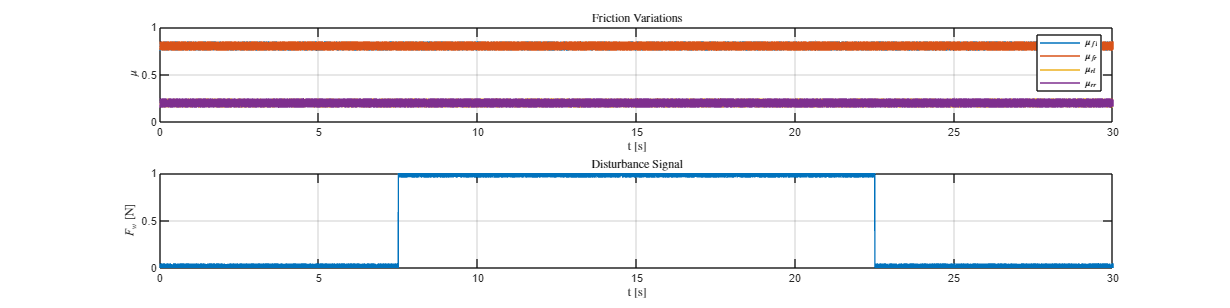

% Friction variation and disturbance

rng(1,"twister"); % Fix random seed and algorithm

% Friction
u1_signal = ones(1,30000)*0.8;
u2_signal = ones(1,30000)*0.8;
u3_signal = ones(1,30000)*0.2;
u4_signal = ones(1,30000)*0.2;
u1_signal = u1_signal - 0.05 + 0.1 * rand(1, length(u1_signal));
u2_signal = u2_signal - 0.05 + 0.1 * rand(1, length(u2_signal));
u3_signal = u3_signal - 0.05 + 0.1 * rand(1, length(u3_signal));
u4_signal = u4_signal - 0.05 + 0.1 * rand(1, length(u4_signal));

% Disturbance
w_signal = [zeros(1,7500) ones(1,15000) zeros(1,7500)];
w_signal = w_signal - 0.05 + 0.1*(max(w_signal)) * rand(1, length(w_signal));

% Plot
t=1:30000;
fig = figure(); 
fig.Position(3:4) = [4000, 1000];
% Friction
subplot(2,1,1)
plot(t/1000,u1_signal)
hold on;
plot(t/1000,u2_signal)
plot(t/1000,u3_signal)
plot(t/1000,u4_signal)
legend('$\mu_{fl}$','$\mu_{fr}$','$\mu_{rl}$','$\mu_{rr}$','Interpreter','latex','Location','northeast')
xlabel('t [s]','Interpreter','latex')
ylabel('$\mu$','Interpreter','latex')
ylim([0,1]);
title('Friction Variations','Interpreter','latex')
grid on;
hold off;
% Disturbance
subplot(2,1,2)
plot(t/1000,w_signal)
xlabel('t [s]','Interpreter','latex')
ylabel('$F_w$ [N]','Interpreter','latex')
ylim([0,1]);
title('Disturbance Signal','Interpreter','latex')
grid on;

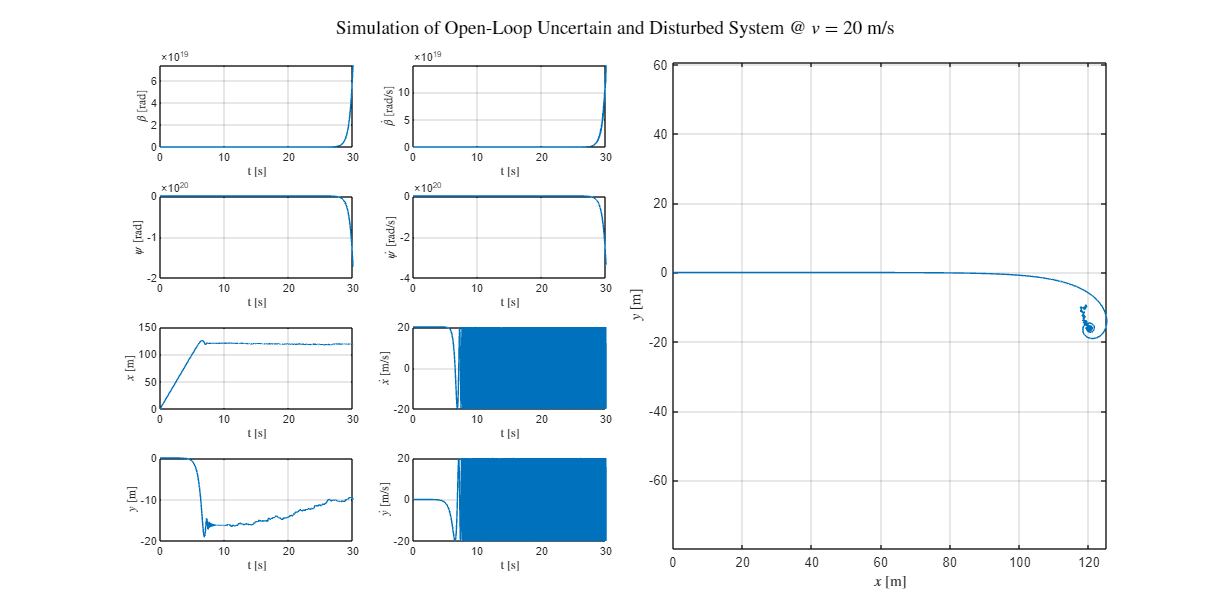

% Simulate straight-line motion with varying friction and disturbance

% Initialization
dt = 0.001; % Simulation timestep [s]
v = 0.35; % Vehicle velocity [m/s]
X = [];
X(:,1) = [0;0];
X_dot = [];
Psi = [];
Psi(1) = 0;
Beta = [];
Vx = [];
Vy = [];
Px = [];
Px(1) = 0;
Py = [];
Py(1) = 0;

% Simulation at each millisecond
for t=1:30000
    system_ol = psinfo(S_ol, 'eval', [u1_signal(t) u2_signal(t) u3_signal(t) u4_signal(t)]);
    [A_ol, B_ol, C_ol, D_ol] = ltiss(system_ol);
    X_dot(:,t) = A_ol*X(:,t) + B_ol*[(w_signal(t).*cos(Psi(t))); [0;0;0;0]];
    X(:,t+1) = X(:,t) + X_dot(:,t)*dt;
    Beta(t) = X(1,t);
    Psi(t+1) = Psi(t) + X(2,t)*dt;
    Vx(t) = v*cos(Psi(t) + Beta(t));
    Vy(t) = v*sin(Psi(t) + Beta(t));
    Px(t+1) = Px(t) + Vx(t)*dt;
    Py(t+1) = Py(t) + Vy(t)*dt;
end
BETA = Beta;
BETA_DOT = X_dot(1,:);
PSI = Psi;
PSI_DOT = X(2,:);
PX = Px;
VX = Vx;
PY = Py;
VY = Vy;

% Plot
t=1:30000;
fig = figure(); 
fig.Position(3:4) = [1500, 750];
% Plot states
subplot(4,4,1)
plot(t/1000,BETA(:,1:end)')
xlabel('t [s]','Interpreter','latex')
ylabel('$\beta$ [rad]','Interpreter','latex')
grid('on')
subplot(4,4,2)
plot(t/1000,BETA_DOT(:,1:end)')
xlabel('t [s]','Interpreter','latex')
ylabel('$\dot{\beta}$ [rad/s]','Interpreter','latex')
grid('on')
subplot(4,4,5)
plot(t/1000,PSI(:,1:end-1)')
xlabel('t [s]','Interpreter','latex')
ylabel('$\psi$ [rad]','Interpreter','latex')
grid('on')
subplot(4,4,6)
plot(t/1000,PSI_DOT(:,1:end-1)')
xlabel('t [s]','Interpreter','latex')
ylabel('$\dot{\psi}$ [rad/s]','Interpreter','latex')
grid('on')
subplot(4,4,9)
plot(t/1000,PX(:,1:end-1)')
xlabel('t [s]','Interpreter','latex')
ylabel('$x$ [m]','Interpreter','latex')
grid('on')
subplot(4,4,10)
plot(t/1000,VX(:,1:end)')
xlabel('t [s]','Interpreter','latex')
ylabel('$\dot{x}$ [m/s]','Interpreter','latex')
grid('on')
subplot(4,4,13)
plot(t/1000,PY(:,1:end-1)')
xlabel('t [s]','Interpreter','latex')
ylabel('$y$ [m]','Interpreter','latex')
grid('on')
subplot(4,4,14)
plot(t/1000,VY(:,1:end)')
xlabel('t [s]','Interpreter','latex')
ylabel('$\dot{y}$ [m/s]','Interpreter','latex')
grid('on')
% Plot trajectory
subplot(4,4,[3,4,7,8,11,12,15,16])
plot(PX(:,1:end-1)',PY(:,1:end-1)')
xlabel('$x$ [m]','Interpreter','latex')
ylabel('$y$ [m]','Interpreter','latex')
axis equal
grid('on')
% Common title and legend
sgtitle('Simulation of Open-Loop Uncertain and Disturbed System @ $v = 0.35$ m/s','Interpreter','latex')

## Controller Design

% region = lmireg; % Pole placement constraint (intersection of the left half-plane with x < –0.1 and of the sector centered at the origin and with inner angle 3π/4)
region = [0.2000 + 1.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   1.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i;
          0.0000 + 0.0000i   0.0000 + 2.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.9239 + 0.0000i  -0.3827 + 0.0000i;
          0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.3827 + 0.0000i   0.9239 + 0.0000i];

g1_opt_global = msfsyn(S_ol, size(By2), [0 0 1 0], region) % Optimal quadratic H∞ performance subject to the pole placement constraint


 Optimization of the H-infinity performance G :
 ----------------------------------------------

 Solver for linear objective minimization under LMI constraints 

 Iterations   :    Best objective value so far 
 
     1
     2
     3
     4
     5                  87.009423
     6                   8.057242
     7                   8.057242
     8                   3.605377
     9                   3.605377
    10                   1.316814
    11                   1.316814
    12                   1.316814
    13                   0.306918
    14                   0.252864
    15                   0.252864
    16                   0.147300
    17                   0.147300
    18                   0.147300
    19                   0.060891
    20                   0.060891
    21                   0.060891
    22                   0.060891
    23                   0.041812
    24                   0.041812
    25                   0.036825
    26                   0.036825
***       

g1_opt_global = 0.0260

g1_opt = []; % Array to store γ1* (Γee)
g2_opt = []; % Array to store γ2* (Γep)
K = []; % Array to store state-feedback controller gain K
S_cl = []; % Array to store closed-loop system representations
X = []; % Array to store corresponding Lyapunov matrices

for g = g1_opt_global:0.01:0.25 % Bound on H∞ performance
    [g1_opt(end+1), g2_opt(end+1), K(:,:,end+1), S_cl(:,:,end+1), X(:,:,end+1)] = msfsyn(S_ol, size(By2), [g 0 0 1], region); % For a prescribed H∞ performance g>0, compute the best H2 performance g2opt
end


 Optimization of   0.000 * G^2 +  1.000 * H^2 :
 ----------------------------------------------

 Solver for linear objective minimization under LMI constraints 

 Iterations   :    Best objective value so far 
 
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10
    11
    12
    13
    14
    15
    16
    17
    18
    19
    20
    21
    22                   0.207323
    23                   0.051874
    24                   0.051874
***                 new lower bound:    -5.544293
    25                   0.037908
***                 new lower bound:    -1.374275
    26                   0.037908
***                 new lower bound:    -0.565406
    27                   0.027875
***                 new lower bound:    -0.436138
    28                   0.027875
***                 new lower bound:    -0.297301
    29                   0.021787
***                 new lower bound:    -0.204550
    30                   0.021787
***                 new lower bou

## Closed-Loop System

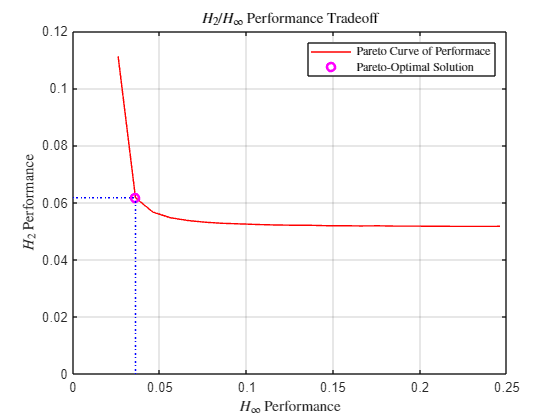

% Find Pareto-optimal solution
dist = sqrt(g1_opt.^2 + g2_opt.^2);
idx_popt = find(dist == min(dist));
g1_popt = g1_opt(idx_popt); % γ1* (Γee)
g2_popt = g2_opt(idx_popt); % γ2* (Γep)
K = K(:,:,idx_popt); % State-feedback controller gain K
S_cl = S_cl(:,:,idx_popt); % Closed-loop system representation
X = X(:,:,idx_popt); % Lyapunov matrix

% Plot
figure()
plot(g1_opt, g2_opt, 'r-')
hold on
plot(g1_popt, g2_popt, 'mo', LineWidth=2)
plot([0, g1_popt], [g2_popt, g2_popt], 'b:');
plot([g1_popt, g1_popt], [0, g2_popt], 'b:');
xlabel('$H_{\infty}$ Performance', 'Interpreter','latex')
ylabel('$H_2$ Performance', 'Interpreter','latex')
legend('Pareto Curve of Performace', 'Pareto-Optimal Solution', 'Interpreter','latex')
hold off
title('$H_2/H_{\infty}$ Performance Tradeoff','Interpreter','latex');
grid('on')

psinfo(S_cl); % Print closed-loop system information

Polytopic model with 16 vertex systems 
    Each system has 2 state(s), 1 input(s), and 12 output(s)



% Test robust stability of closed-loop system via parametric Lyapunov functions
[tmin_cl, Q0_cl, Q1_cl, Q2_cl, Q3_cl] = pdlstab(S_cl, [0 0])


 Solver for LMI feasibility problems L(x) < R(x)
    This solver minimizes  t  subject to  L(x) < R(x) + t*I
    The best value of t should be negative for feasibility

 Iteration   :    Best value of t so far 
 
     1                        0.232109
     2                        0.047558
     3                        0.047558
     4                        0.012415
     5                        0.012415
     6                    9.993207e-03
     7                    9.993207e-03
     8                    9.084775e-03
     9                    7.786999e-03
    10                       -0.102098

 Result:  best value of t:    -0.102098
          f-radius saturation:  0.037% of R =  1.00e+07
 
 This system is stable in the specified parameter range


tmin_cl = -0.1021

Q0_cl =   233.9261   35.5462
   35.5462   10.2701


Q1_cl =   233.9261   35.5462
   35.5462   10.2701


Q2_cl =   233.9261   35.5462
   35.5462   10.2701


Q3_cl =   233.9261   35.5462
   35.5462   10.2701


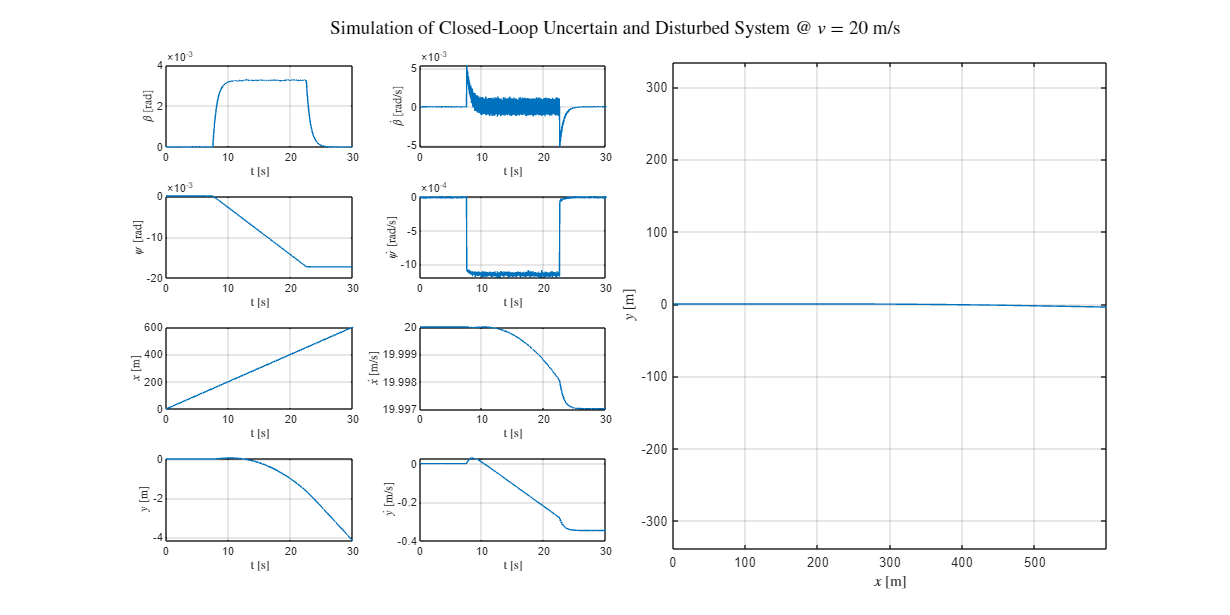

% Simulate straight-line motion with varying friction and disturbance

% Initialization
dt = 0.001; % Simulation timestep [s]
v = 0.35; % Vehicle velocity [m/s]
X = [];
X(:,1) = [0;0];
X_dot = [];
Psi = [];
Psi(1) = 0;
Beta = [];
Vx = [];
Vy = [];
Px = [];
Px(1) = 0;
Py = [];
Py(1) = 0;

% Simulation at each millisecond
for t=1:30000
    system_cl = psinfo(S_cl, 'eval', polydec(pv, [u1_signal(t) u2_signal(t) u3_signal(t) u4_signal(t)]));
    [A_cl, B_cl, C_cl, D_cl] = ltiss(system_cl);
    X_dot(:,t) = A_cl*X(:,t) + B_cl*(w_signal(:,t).*cos(Psi(t)));
    X(:,t+1) = X(:,t) + X_dot(:,t)*dt;
    Beta(t) = X(1,t);
    Psi(t+1) = Psi(t) + X(2,t)*dt;
    Vx(t) = v*cos(Psi(t) + Beta(t));
    Vy(t) = v*sin(Psi(t) + Beta(t));
    Px(t+1) = Px(t) + Vx(t)*dt;
    Py(t+1) = Py(t) + Vy(t)*dt;
end
BETA = Beta;
BETA_DOT = X_dot(1,:);
PSI = Psi;
PSI_DOT = X(2,:);
PX = Px;
VX = Vx;
PY = Py;
VY = Vy;

% Plot
t=1:30000;
fig = figure(); 
fig.Position(3:4) = [1500, 750];
% Plot states
subplot(4,4,1)
plot(t/1000,BETA(:,1:end)')
xlabel('t [s]','Interpreter','latex')
ylabel('$\beta$ [rad]','Interpreter','latex')
grid('on')
subplot(4,4,2)
plot(t/1000,BETA_DOT(:,1:end)')
xlabel('t [s]','Interpreter','latex')
ylabel('$\dot{\beta}$ [rad/s]','Interpreter','latex')
grid('on')
subplot(4,4,5)
plot(t/1000,PSI(:,1:end-1)')
xlabel('t [s]','Interpreter','latex')
ylabel('$\psi$ [rad]','Interpreter','latex')
grid('on')
subplot(4,4,6)
plot(t/1000,PSI_DOT(:,1:end-1)')
xlabel('t [s]','Interpreter','latex')
ylabel('$\dot{\psi}$ [rad/s]','Interpreter','latex')
grid('on')
subplot(4,4,9)
plot(t/1000,PX(:,1:end-1)')
xlabel('t [s]','Interpreter','latex')
ylabel('$x$ [m]','Interpreter','latex')
grid('on')
subplot(4,4,10)
plot(t/1000,VX(:,1:end)')
xlabel('t [s]','Interpreter','latex')
ylabel('$\dot{x}$ [m/s]','Interpreter','latex')
grid('on')
subplot(4,4,13)
plot(t/1000,PY(:,1:end-1)')
xlabel('t [s]','Interpreter','latex')
ylabel('$y$ [m]','Interpreter','latex')
grid('on')
subplot(4,4,14)
plot(t/1000,VY(:,1:end)')
xlabel('t [s]','Interpreter','latex')
ylabel('$\dot{y}$ [m/s]','Interpreter','latex')
grid('on')
% Plot trajectory
subplot(4,4,[3,4,7,8,11,12,15,16])
plot(PX(:,1:end-1)',PY(:,1:end-1)')
xlabel('$x$ [m]','Interpreter','latex')
ylabel('$y$ [m]','Interpreter','latex')
axis equal
grid('on')
% Common title and legend
sgtitle('Simulation of Closed-Loop Uncertain and Disturbed System @ $v = 0.35$ m/s','Interpreter','latex')

## Open-Loop vs. Closed Loop System Performance

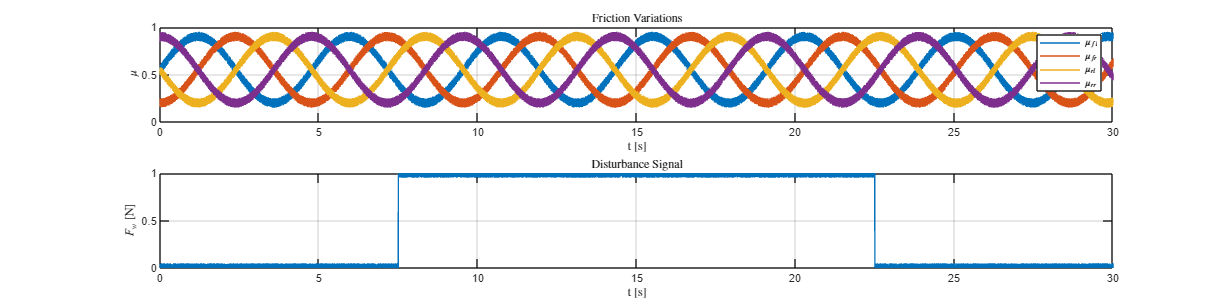

% Friction variation and disturbance

rng(1,"twister"); % Fix random seed and algorithm

% Friction
theta = linspace(0, 2*pi, 30000);
frequency = 1;
u1_signal = 0.35 * sin(2*pi*frequency*theta) + 0.55;
u2_signal = 0.35 * sin(2*pi*frequency*theta - pi/2) + 0.55;
u3_signal = 0.35 * sin(2*pi*frequency*theta - pi) + 0.55;
u4_signal = 0.35 * sin(2*pi*frequency*theta - 3*pi/2) + 0.55;
u1_signal = u1_signal - 0.05 + 0.1 * rand(1, length(u1_signal));
u2_signal = u2_signal - 0.05 + 0.1 * rand(1, length(u2_signal));
u3_signal = u3_signal - 0.05 + 0.1 * rand(1, length(u3_signal));
u4_signal = u4_signal - 0.05 + 0.1 * rand(1, length(u4_signal));

% Disturbance
w_signal = [zeros(1,7500) ones(1,15000) zeros(1,7500)];
w_signal = w_signal - 0.05 + 0.1*(max(w_signal)) * rand(1, length(w_signal));

% Plot
t=1:30000;
fig = figure(); 
fig.Position(3:4) = [4000, 1000];
% Friction
subplot(2,1,1)
plot(t/1000,u1_signal)
hold on;
plot(t/1000,u2_signal)
plot(t/1000,u3_signal)
plot(t/1000,u4_signal)
legend('$\mu_{fl}$','$\mu_{fr}$','$\mu_{rl}$','$\mu_{rr}$','Interpreter','latex','Location','northeast')
xlabel('t [s]','Interpreter','latex')
ylabel('$\mu$','Interpreter','latex')
ylim([0,1]);
title('Friction Variations','Interpreter','latex')
grid on;
hold off;
% Disturbance
subplot(2,1,2)
plot(t/1000,w_signal)
xlabel('t [s]','Interpreter','latex')
ylabel('$F_w$ [N]','Interpreter','latex')
ylim([0,1]);
title('Disturbance Signal','Interpreter','latex')
grid on;

### Stabilizing Controller

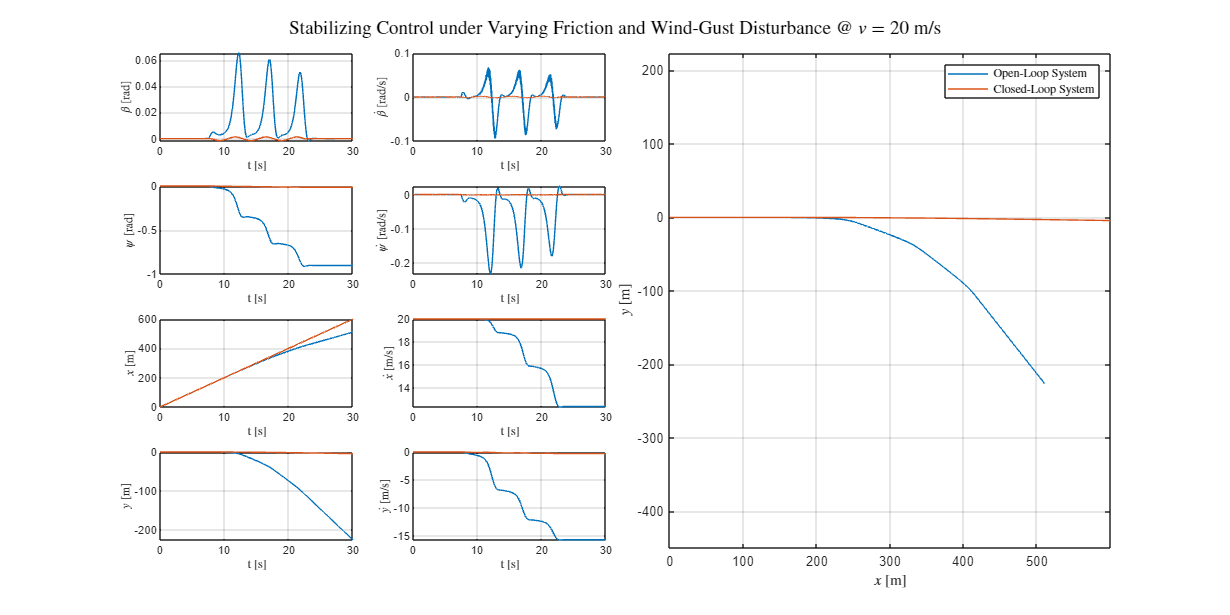

% Simulate open-loop system with varying friction and disturbance

% Initialization
dt = 0.001; % Simulation timestep [s]
v = 0.35; % Vehicle velocity [m/s]
X = [];
X(:,1) = [0;0];
X_dot = [];
Psi = [];
Psi(1) = 0;
Beta = [];
Vx = [];
Vy = [];
Px = [];
Px(1) = 0;
Py = [];
Py(1) = 0;

% Simulation at each millisecond
for t=1:30000
    system_ol = psinfo(S_ol, 'eval', [u1_signal(t) u2_signal(t) u3_signal(t) u4_signal(t)]);
    [A_ol, B_ol, C_ol, D_ol] = ltiss(system_ol);
    X_dot(:,t) = A_ol*X(:,t) + B_ol*[(w_signal(t).*cos(Psi(t))); [0;0;0;0]];
    X(:,t+1) = X(:,t) + X_dot(:,t)*dt;
    Beta(t) = X(1,t);
    Psi(t+1) = Psi(t) + X(2,t)*dt;
    Vx(t) = v*cos(Psi(t) + Beta(t));
    Vy(t) = v*sin(Psi(t) + Beta(t));
    Px(t+1) = Px(t) + Vx(t)*dt;
    Py(t+1) = Py(t) + Vy(t)*dt;
end
BETA_OL = Beta;
BETA_DOT_OL = X_dot(1,:);
PSI_OL = Psi;
PSI_DOT_OL = X(2,:);
PX_OL = Px;
VX_OL = Vx;
PY_OL = Py;
VY_OL = Vy;

% Simulate closed-loop system with varying friction and disturbance

% Initialization
dt = 0.001; % Simulation timestep [s]
v = 0.35; % Vehicle velocity [m/s]
X = [];
X(:,1) = [0;0];
X_dot = [];
Psi = [];
Psi(1) = 0;
Beta = [];
Vx = [];
Vy = [];
Px = [];
Px(1) = 0;
Py = [];
Py(1) = 0;

% Simulation at each millisecond
for t=1:30000
    system_cl = psinfo(S_cl, 'eval', polydec(pv, [u1_signal(t) u2_signal(t) u3_signal(t) u4_signal(t)]));
    [A_cl, B_cl, C_cl, D_cl] = ltiss(system_cl);
    X_dot(:,t) = A_cl*X(:,t) + B_cl*(w_signal(:,t).*cos(Psi(t)));
    X(:,t+1) = X(:,t) + X_dot(:,t)*dt;
    Beta(t) = X(1,t);
    Psi(t+1) = Psi(t) + X(2,t)*dt;
    Vx(t) = v*cos(Psi(t) + Beta(t));
    Vy(t) = v*sin(Psi(t) + Beta(t));
    Px(t+1) = Px(t) + Vx(t)*dt;
    Py(t+1) = Py(t) + Vy(t)*dt;
end
BETA_CL = Beta;
BETA_DOT_CL = X_dot(1,:);
PSI_CL = Psi;
PSI_DOT_CL = X(2,:);
PX_CL = Px;
VX_CL = Vx;
PY_CL = Py;
VY_CL = Vy;

% Plot
t=1:30000;
fig = figure(); 
fig.Position(3:4) = [1500, 750];
% Plot states
subplot(4,4,1)
plot(t/1000,BETA_OL(:,1:end)')
hold on
plot(t/1000,BETA_CL(:,1:end)')
xlabel('t [s]','Interpreter','latex')
ylabel('$\beta$ [rad]','Interpreter','latex')
grid('on')
subplot(4,4,2)
plot(t/1000,BETA_DOT_OL(:,1:end)')
hold on
plot(t/1000,BETA_DOT_CL(:,1:end)')
xlabel('t [s]','Interpreter','latex')
ylabel('$\dot{\beta}$ [rad/s]','Interpreter','latex')
grid('on')
subplot(4,4,5)
plot(t/1000,PSI_OL(:,1:end-1)')
hold on
plot(t/1000,PSI_CL(:,1:end-1)')
xlabel('t [s]','Interpreter','latex')
ylabel('$\psi$ [rad]','Interpreter','latex')
grid('on')
subplot(4,4,6)
plot(t/1000,PSI_DOT_OL(:,1:end-1)')
hold on
plot(t/1000,PSI_DOT_CL(:,1:end-1)')
xlabel('t [s]','Interpreter','latex')
ylabel('$\dot{\psi}$ [rad/s]','Interpreter','latex')
grid('on')
subplot(4,4,9)
plot(t/1000,PX_OL(:,1:end-1)')
hold on
plot(t/1000,PX_CL(:,1:end-1)')
xlabel('t [s]','Interpreter','latex')
ylabel('$x$ [m]','Interpreter','latex')
grid('on')
subplot(4,4,10)
plot(t/1000,VX_OL(:,1:end)')
hold on
plot(t/1000,VX_CL(:,1:end)')
xlabel('t [s]','Interpreter','latex')
ylabel('$\dot{x}$ [m/s]','Interpreter','latex')
grid('on')
subplot(4,4,13)
plot(t/1000,PY_OL(:,1:end-1)')
hold on
plot(t/1000,PY_CL(:,1:end-1)')
xlabel('t [s]','Interpreter','latex')
ylabel('$y$ [m]','Interpreter','latex')
grid('on')
subplot(4,4,14)
plot(t/1000,VY_OL(:,1:end)')
hold on
plot(t/1000,VY_CL(:,1:end)')
xlabel('t [s]','Interpreter','latex')
ylabel('$\dot{y}$ [m/s]','Interpreter','latex')
grid('on')
% Plot trajectory
subplot(4,4,[3,4,7,8,11,12,15,16])
plot(PX_OL(:,1:end-1)',PY_OL(:,1:end-1)')
hold on
plot(PX_CL(:,1:end-1)',PY_CL(:,1:end-1)')
xlabel('$x$ [m]','Interpreter','latex')
ylabel('$y$ [m]','Interpreter','latex')
axis equal
grid('on')
% Common title and legend
sgtitle('Stabilizing Control under Varying Friction and Wind-Gust Disturbance @ $v = 0.35$ m/s','Interpreter','latex')
legend('Open-Loop System', 'Closed-Loop System', ...
       'Interpreter','latex','Location','northeast')

### Tracking Controller

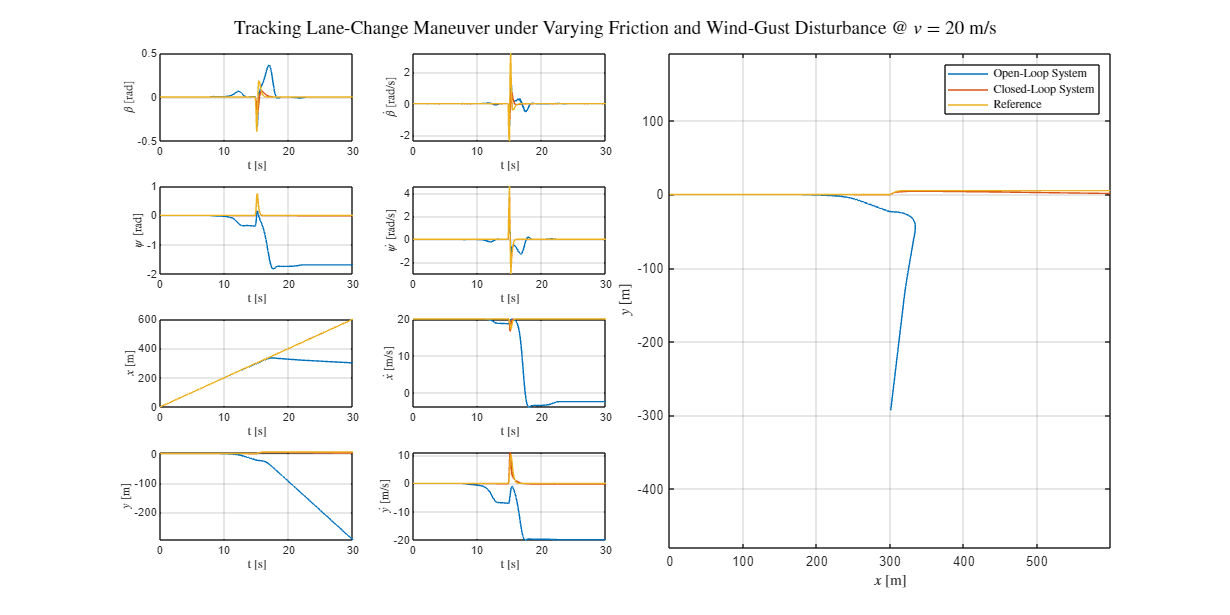

% Reference states (LC = lane-change, SP = skidpad, FH = fishhook, SL = slalom)
BETA_REF = BETA_LC(5,:);
BETA_DOT_REF = BETA_DOT_LC(5,:);
PSI_REF = PSI_LC(5,:);
PSI_DOT_REF = PSI_DOT_LC(5,:);
PX_REF = PX_LC(5,:);
VX_REF = VX_LC(5,:);
PY_REF = PY_LC(5,:);
VY_REF = VY_LC(5,:);
DELTA_REF = u_lane_change;

% Simulate open-loop system with varying friction and disturbance

% Initialization
dt = 0.001; % Simulation timestep [s]
v = 0.35; % Vehicle velocity [m/s]
X = [];
X(:,1) = [0;0];
X_dot = [];
Psi = [];
Psi(1) = 0;
Beta = [];
Vx = [];
Vy = [];
Px = [];
Px(1) = 0;
Py = [];
Py(1) = 0;

% Simulation at each millisecond
for t=1:30000
    system_ol = psinfo(S_ol, 'eval', [u1_signal(t) u2_signal(t) u3_signal(t) u4_signal(t)]);
    [A_ol, B_ol, C_ol, D_ol] = ltiss(system_ol);
    X_dot(:,t) = A_ol*X(:,t) + B_ol*[(w_signal(:,t).*cos(Psi(t))); DELTA_REF(:,t)];
    X(:,t+1) = X(:,t) + X_dot(:,t)*dt;
    Beta(t) = X(1,t);
    Psi(t+1) = Psi(t) + X(2,t)*dt;
    Vx(t) = v*cos(Psi(t) + Beta(t));
    Vy(t) = v*sin(Psi(t) + Beta(t));
    Px(t+1) = Px(t) + Vx(t)*dt;
    Py(t+1) = Py(t) + Vy(t)*dt;
end
BETA_OL = Beta;
BETA_DOT_OL = X_dot(1,:);
PSI_OL = Psi;
PSI_DOT_OL = X(2,:);
PX_OL = Px;
VX_OL = Vx;
PY_OL = Py;
VY_OL = Vy;

% Simulate closed-loop system with varying friction and disturbance

% Initialization
dt = 0.001; % Simulation timestep [s]
v = 0.35; % Vehicle velocity [m/s]
X = [];
X(:,1) = [0;0];
X_dot = [];
Psi = [];
Psi(1) = 0;
Beta = [];
Vx = [];
Vy = [];
Px = [];
Px(1) = 0;
Py = [];
Py(1) = 0;

% Simulation at each millisecond
for t=1:30000
    system_cl = psinfo(S_cl, 'eval', polydec(pv, [u1_signal(t) u2_signal(t) u3_signal(t) u4_signal(t)]));
    [A_cl, B_cl, C_cl, D_cl] = ltiss(system_cl);
    X_dot(:,t) = A_cl*(X(:,t) - [BETA_REF(t);PSI_DOT_REF(t)]) + B_cl*(w_signal(:,t).*cos(Psi(t)));
    X(:,t+1) = X(:,t) + X_dot(:,t)*dt;
    Beta(t) = X(1,t);
    Psi(t+1) = Psi(t) + X(2,t)*dt;
    Vx(t) = v*cos(Psi(t) + Beta(t));
    Vy(t) = v*sin(Psi(t) + Beta(t));
    Px(t+1) = Px(t) + Vx(t)*dt;
    Py(t+1) = Py(t) + Vy(t)*dt;
end
BETA_CL = Beta;
BETA_DOT_CL = X_dot(1,:);
PSI_CL = Psi;
PSI_DOT_CL = X(2,:);
PX_CL = Px;
VX_CL = Vx;
PY_CL = Py;
VY_CL = Vy;

% Plot
t=1:30000;
fig = figure(); 
fig.Position(3:4) = [1500, 750];
% Plot states
subplot(4,4,1)
plot(t/1000,BETA_OL(:,1:end)')
hold on
plot(t/1000,BETA_CL(:,1:end)')
plot(t/1000,BETA_REF(:,1:end)')
xlabel('t [s]','Interpreter','latex')
ylabel('$\beta$ [rad]','Interpreter','latex')
grid('on')
subplot(4,4,2)
plot(t/1000,BETA_DOT_OL(:,1:end)')
hold on
plot(t/1000,BETA_DOT_CL(:,1:end)')
plot(t/1000,BETA_DOT_REF(:,1:end)')
xlabel('t [s]','Interpreter','latex')
ylabel('$\dot{\beta}$ [rad/s]','Interpreter','latex')
grid('on')
subplot(4,4,5)
plot(t/1000,PSI_OL(:,1:end-1)')
hold on
plot(t/1000,PSI_CL(:,1:end-1)')
plot(t/1000,PSI_REF(:,1:end-1)')
xlabel('t [s]','Interpreter','latex')
ylabel('$\psi$ [rad]','Interpreter','latex')
grid('on')
subplot(4,4,6)
plot(t/1000,PSI_DOT_OL(:,1:end-1)')
hold on
plot(t/1000,PSI_DOT_CL(:,1:end-1)')
plot(t/1000,PSI_DOT_REF(:,1:end-1)')
xlabel('t [s]','Interpreter','latex')
ylabel('$\dot{\psi}$ [rad/s]','Interpreter','latex')
grid('on')
subplot(4,4,9)
plot(t/1000,PX_OL(:,1:end-1)')
hold on
plot(t/1000,PX_CL(:,1:end-1)')
plot(t/1000,PX_REF(:,1:end-1)')
xlabel('t [s]','Interpreter','latex')
ylabel('$x$ [m]','Interpreter','latex')
grid('on')
subplot(4,4,10)
plot(t/1000,VX_OL(:,1:end)')
hold on
plot(t/1000,VX_CL(:,1:end)')
plot(t/1000,VX_REF(:,1:end)')
xlabel('t [s]','Interpreter','latex')
ylabel('$\dot{x}$ [m/s]','Interpreter','latex')
grid('on')
subplot(4,4,13)
plot(t/1000,PY_OL(:,1:end-1)')
hold on
plot(t/1000,PY_CL(:,1:end-1)')
plot(t/1000,PY_REF(:,1:end-1)')
xlabel('t [s]','Interpreter','latex')
ylabel('$y$ [m]','Interpreter','latex')
grid('on')
subplot(4,4,14)
plot(t/1000,VY_OL(:,1:end)')
hold on
plot(t/1000,VY_CL(:,1:end)')
plot(t/1000,VY_REF(:,1:end)')
xlabel('t [s]','Interpreter','latex')
ylabel('$\dot{y}$ [m/s]','Interpreter','latex')
grid('on')
% Plot trajectory
subplot(4,4,[3,4,7,8,11,12,15,16])
plot(PX_OL(:,1:end-1)',PY_OL(:,1:end-1)')
hold on
plot(PX_CL(:,1:end-1)',PY_CL(:,1:end-1)')
plot(PX_REF(:,1:end-1)',PY_REF(:,1:end-1)')
xlabel('$x$ [m]','Interpreter','latex')
ylabel('$y$ [m]','Interpreter','latex')
axis equal
grid('on')
% Common title and legend
sgtitle('Tracking Lane-Change Maneuver under Varying Friction and Wind-Gust Disturbance @ $v = 0.35$ m/s','Interpreter','latex')
legend('Open-Loop System', 'Closed-Loop System', 'Reference', ...
       'Interpreter','latex','Location','northeast')

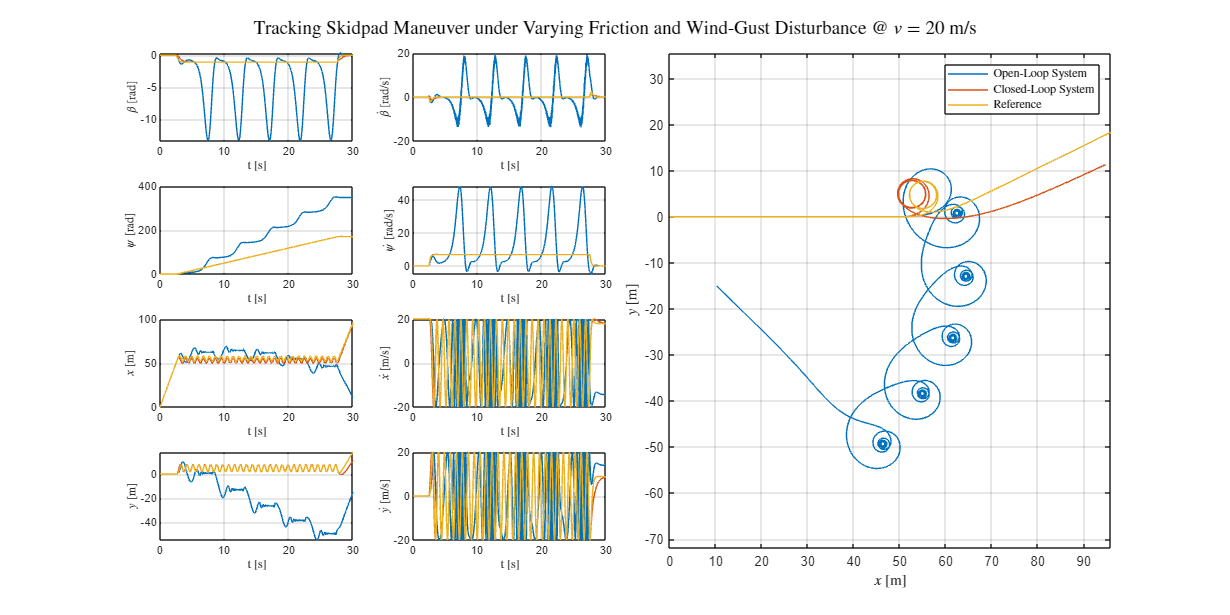

% Reference states (LC = lane-change, SP = skidpad, FH = fishhook, SL = slalom)
BETA_REF = BETA_SP(5,:);
BETA_DOT_REF = BETA_DOT_SP(5,:);
PSI_REF = PSI_SP(5,:);
PSI_DOT_REF = PSI_DOT_SP(5,:);
PX_REF = PX_SP(5,:);
VX_REF = VX_SP(5,:);
PY_REF = PY_SP(5,:);
VY_REF = VY_SP(5,:);
DELTA_REF = u_skidpad;

% Simulate open-loop system with varying friction and disturbance

% Initialization
dt = 0.001; % Simulation timestep [s]
v = 0.35; % Vehicle velocity [m/s]
X = [];
X(:,1) = [0;0];
X_dot = [];
Psi = [];
Psi(1) = 0;
Beta = [];
Vx = [];
Vy = [];
Px = [];
Px(1) = 0;
Py = [];
Py(1) = 0;

% Simulation at each millisecond
for t=1:30000
    system_ol = psinfo(S_ol, 'eval', [u1_signal(t) u2_signal(t) u3_signal(t) u4_signal(t)]);
    [A_ol, B_ol, C_ol, D_ol] = ltiss(system_ol);
    X_dot(:,t) = A_ol*X(:,t) + B_ol*[(w_signal(:,t).*cos(Psi(t))); DELTA_REF(:,t)];
    X(:,t+1) = X(:,t) + X_dot(:,t)*dt;
    Beta(t) = X(1,t);
    Psi(t+1) = Psi(t) + X(2,t)*dt;
    Vx(t) = v*cos(Psi(t) + Beta(t));
    Vy(t) = v*sin(Psi(t) + Beta(t));
    Px(t+1) = Px(t) + Vx(t)*dt;
    Py(t+1) = Py(t) + Vy(t)*dt;
end
BETA_OL = Beta;
BETA_DOT_OL = X_dot(1,:);
PSI_OL = Psi;
PSI_DOT_OL = X(2,:);
PX_OL = Px;
VX_OL = Vx;
PY_OL = Py;
VY_OL = Vy;

% Simulate closed-loop system with varying friction and disturbance

% Initialization
dt = 0.001; % Simulation timestep [s]
v = 0.35; % Vehicle velocity [m/s]
X = [];
X(:,1) = [0;0];
X_dot = [];
Psi = [];
Psi(1) = 0;
Beta = [];
Vx = [];
Vy = [];
Px = [];
Px(1) = 0;
Py = [];
Py(1) = 0;

% Simulation at each millisecond
for t=1:30000
    system_cl = psinfo(S_cl, 'eval', polydec(pv, [u1_signal(t) u2_signal(t) u3_signal(t) u4_signal(t)]));
    [A_cl, B_cl, C_cl, D_cl] = ltiss(system_cl);
    X_dot(:,t) = A_cl*(X(:,t) - [BETA_REF(t);PSI_DOT_REF(t)]) + B_cl*(w_signal(:,t).*cos(Psi(t)));
    X(:,t+1) = X(:,t) + X_dot(:,t)*dt;
    Beta(t) = X(1,t);
    Psi(t+1) = Psi(t) + X(2,t)*dt;
    Vx(t) = v*cos(Psi(t) + Beta(t));
    Vy(t) = v*sin(Psi(t) + Beta(t));
    Px(t+1) = Px(t) + Vx(t)*dt;
    Py(t+1) = Py(t) + Vy(t)*dt;
end
BETA_CL = Beta;
BETA_DOT_CL = X_dot(1,:);
PSI_CL = Psi;
PSI_DOT_CL = X(2,:);
PX_CL = Px;
VX_CL = Vx;
PY_CL = Py;
VY_CL = Vy;

% Plot
t=1:30000;
fig = figure(); 
fig.Position(3:4) = [1500, 750];
% Plot states
subplot(4,4,1)
plot(t/1000,BETA_OL(:,1:end)')
hold on
plot(t/1000,BETA_CL(:,1:end)')
plot(t/1000,BETA_REF(:,1:end)')
xlabel('t [s]','Interpreter','latex')
ylabel('$\beta$ [rad]','Interpreter','latex')
grid('on')
subplot(4,4,2)
plot(t/1000,BETA_DOT_OL(:,1:end)')
hold on
plot(t/1000,BETA_DOT_CL(:,1:end)')
plot(t/1000,BETA_DOT_REF(:,1:end)')
xlabel('t [s]','Interpreter','latex')
ylabel('$\dot{\beta}$ [rad/s]','Interpreter','latex')
grid('on')
subplot(4,4,5)
plot(t/1000,PSI_OL(:,1:end-1)')
hold on
plot(t/1000,PSI_CL(:,1:end-1)')
plot(t/1000,PSI_REF(:,1:end-1)')
xlabel('t [s]','Interpreter','latex')
ylabel('$\psi$ [rad]','Interpreter','latex')
grid('on')
subplot(4,4,6)
plot(t/1000,PSI_DOT_OL(:,1:end-1)')
hold on
plot(t/1000,PSI_DOT_CL(:,1:end-1)')
plot(t/1000,PSI_DOT_REF(:,1:end-1)')
xlabel('t [s]','Interpreter','latex')
ylabel('$\dot{\psi}$ [rad/s]','Interpreter','latex')
grid('on')
subplot(4,4,9)
plot(t/1000,PX_OL(:,1:end-1)')
hold on
plot(t/1000,PX_CL(:,1:end-1)')
plot(t/1000,PX_REF(:,1:end-1)')
xlabel('t [s]','Interpreter','latex')
ylabel('$x$ [m]','Interpreter','latex')
grid('on')
subplot(4,4,10)
plot(t/1000,VX_OL(:,1:end)')
hold on
plot(t/1000,VX_CL(:,1:end)')
plot(t/1000,VX_REF(:,1:end)')
xlabel('t [s]','Interpreter','latex')
ylabel('$\dot{x}$ [m/s]','Interpreter','latex')
grid('on')
subplot(4,4,13)
plot(t/1000,PY_OL(:,1:end-1)')
hold on
plot(t/1000,PY_CL(:,1:end-1)')
plot(t/1000,PY_REF(:,1:end-1)')
xlabel('t [s]','Interpreter','latex')
ylabel('$y$ [m]','Interpreter','latex')
grid('on')
subplot(4,4,14)
plot(t/1000,VY_OL(:,1:end)')
hold on
plot(t/1000,VY_CL(:,1:end)')
plot(t/1000,VY_REF(:,1:end)')
xlabel('t [s]','Interpreter','latex')
ylabel('$\dot{y}$ [m/s]','Interpreter','latex')
grid('on')
% Plot trajectory
subplot(4,4,[3,4,7,8,11,12,15,16])
plot(PX_OL(:,1:end-1)',PY_OL(:,1:end-1)')
hold on
plot(PX_CL(:,1:end-1)',PY_CL(:,1:end-1)')
plot(PX_REF(:,1:end-1)',PY_REF(:,1:end-1)')
xlabel('$x$ [m]','Interpreter','latex')
ylabel('$y$ [m]','Interpreter','latex')
axis equal
grid('on')
% Common title and legend
sgtitle('Tracking Skidpad Maneuver under Varying Friction and Wind-Gust Disturbance @ $v = 0.35$ m/s','Interpreter','latex')
legend('Open-Loop System', 'Closed-Loop System', 'Reference', ...
       'Interpreter','latex','Location','northeast')

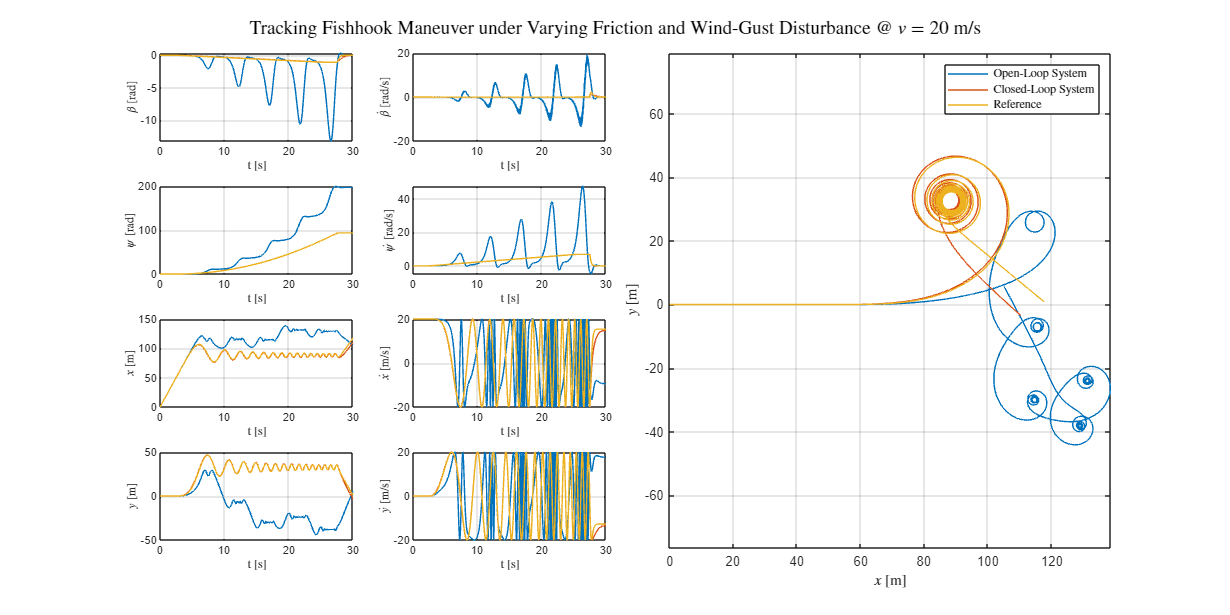

% Reference states (LC = lane-change, SP = skidpad, FH = fishhook, SL = slalom)
BETA_REF = BETA_FH(5,:);
BETA_DOT_REF = BETA_DOT_FH(5,:);
PSI_REF = PSI_FH(5,:);
PSI_DOT_REF = PSI_DOT_FH(5,:);
PX_REF = PX_FH(5,:);
VX_REF = VX_FH(5,:);
PY_REF = PY_FH(5,:);
VY_REF = VY_FH(5,:);
DELTA_REF = u_fishhook;

% Simulate open-loop system with varying friction and disturbance

% Initialization
dt = 0.001; % Simulation timestep [s]
v = 0.35; % Vehicle velocity [m/s]
X = [];
X(:,1) = [0;0];
X_dot = [];
Psi = [];
Psi(1) = 0;
Beta = [];
Vx = [];
Vy = [];
Px = [];
Px(1) = 0;
Py = [];
Py(1) = 0;

% Simulation at each millisecond
for t=1:30000
    system_ol = psinfo(S_ol, 'eval', [u1_signal(t) u2_signal(t) u3_signal(t) u4_signal(t)]);
    [A_ol, B_ol, C_ol, D_ol] = ltiss(system_ol);
    X_dot(:,t) = A_ol*X(:,t) + B_ol*[(w_signal(:,t).*cos(Psi(t))); DELTA_REF(:,t)];
    X(:,t+1) = X(:,t) + X_dot(:,t)*dt;
    Beta(t) = X(1,t);
    Psi(t+1) = Psi(t) + X(2,t)*dt;
    Vx(t) = v*cos(Psi(t) + Beta(t));
    Vy(t) = v*sin(Psi(t) + Beta(t));
    Px(t+1) = Px(t) + Vx(t)*dt;
    Py(t+1) = Py(t) + Vy(t)*dt;
end
BETA_OL = Beta;
BETA_DOT_OL = X_dot(1,:);
PSI_OL = Psi;
PSI_DOT_OL = X(2,:);
PX_OL = Px;
VX_OL = Vx;
PY_OL = Py;
VY_OL = Vy;

% Simulate closed-loop system with varying friction and disturbance

% Initialization
dt = 0.001; % Simulation timestep [s]
v = 0.35; % Vehicle velocity [m/s]
X = [];
X(:,1) = [0;0];
X_dot = [];
Psi = [];
Psi(1) = 0;
Beta = [];
Vx = [];
Vy = [];
Px = [];
Px(1) = 0;
Py = [];
Py(1) = 0;

% Simulation at each millisecond
for t=1:30000
    system_cl = psinfo(S_cl, 'eval', polydec(pv, [u1_signal(t) u2_signal(t) u3_signal(t) u4_signal(t)]));
    [A_cl, B_cl, C_cl, D_cl] = ltiss(system_cl);
    X_dot(:,t) = A_cl*(X(:,t) - [BETA_REF(t);PSI_DOT_REF(t)]) + B_cl*(w_signal(:,t).*cos(Psi(t)));
    X(:,t+1) = X(:,t) + X_dot(:,t)*dt;
    Beta(t) = X(1,t);
    Psi(t+1) = Psi(t) + X(2,t)*dt;
    Vx(t) = v*cos(Psi(t) + Beta(t));
    Vy(t) = v*sin(Psi(t) + Beta(t));
    Px(t+1) = Px(t) + Vx(t)*dt;
    Py(t+1) = Py(t) + Vy(t)*dt;
end
BETA_CL = Beta;
BETA_DOT_CL = X_dot(1,:);
PSI_CL = Psi;
PSI_DOT_CL = X(2,:);
PX_CL = Px;
VX_CL = Vx;
PY_CL = Py;
VY_CL = Vy;

% Plot
t=1:30000;
fig = figure(); 
fig.Position(3:4) = [1500, 750];
% Plot states
subplot(4,4,1)
plot(t/1000,BETA_OL(:,1:end)')
hold on
plot(t/1000,BETA_CL(:,1:end)')
plot(t/1000,BETA_REF(:,1:end)')
xlabel('t [s]','Interpreter','latex')
ylabel('$\beta$ [rad]','Interpreter','latex')
grid('on')
subplot(4,4,2)
plot(t/1000,BETA_DOT_OL(:,1:end)')
hold on
plot(t/1000,BETA_DOT_CL(:,1:end)')
plot(t/1000,BETA_DOT_REF(:,1:end)')
xlabel('t [s]','Interpreter','latex')
ylabel('$\dot{\beta}$ [rad/s]','Interpreter','latex')
grid('on')
subplot(4,4,5)
plot(t/1000,PSI_OL(:,1:end-1)')
hold on
plot(t/1000,PSI_CL(:,1:end-1)')
plot(t/1000,PSI_REF(:,1:end-1)')
xlabel('t [s]','Interpreter','latex')
ylabel('$\psi$ [rad]','Interpreter','latex')
grid('on')
subplot(4,4,6)
plot(t/1000,PSI_DOT_OL(:,1:end-1)')
hold on
plot(t/1000,PSI_DOT_CL(:,1:end-1)')
plot(t/1000,PSI_DOT_REF(:,1:end-1)')
xlabel('t [s]','Interpreter','latex')
ylabel('$\dot{\psi}$ [rad/s]','Interpreter','latex')
grid('on')
subplot(4,4,9)
plot(t/1000,PX_OL(:,1:end-1)')
hold on
plot(t/1000,PX_CL(:,1:end-1)')
plot(t/1000,PX_REF(:,1:end-1)')
xlabel('t [s]','Interpreter','latex')
ylabel('$x$ [m]','Interpreter','latex')
grid('on')
subplot(4,4,10)
plot(t/1000,VX_OL(:,1:end)')
hold on
plot(t/1000,VX_CL(:,1:end)')
plot(t/1000,VX_REF(:,1:end)')
xlabel('t [s]','Interpreter','latex')
ylabel('$\dot{x}$ [m/s]','Interpreter','latex')
grid('on')
subplot(4,4,13)
plot(t/1000,PY_OL(:,1:end-1)')
hold on
plot(t/1000,PY_CL(:,1:end-1)')
plot(t/1000,PY_REF(:,1:end-1)')
xlabel('t [s]','Interpreter','latex')
ylabel('$y$ [m]','Interpreter','latex')
grid('on')
subplot(4,4,14)
plot(t/1000,VY_OL(:,1:end)')
hold on
plot(t/1000,VY_CL(:,1:end)')
plot(t/1000,VY_REF(:,1:end)')
xlabel('t [s]','Interpreter','latex')
ylabel('$\dot{y}$ [m/s]','Interpreter','latex')
grid('on')
% Plot trajectory
subplot(4,4,[3,4,7,8,11,12,15,16])
plot(PX_OL(:,1:end-1)',PY_OL(:,1:end-1)')
hold on
plot(PX_CL(:,1:end-1)',PY_CL(:,1:end-1)')
plot(PX_REF(:,1:end-1)',PY_REF(:,1:end-1)')
xlabel('$x$ [m]','Interpreter','latex')
ylabel('$y$ [m]','Interpreter','latex')
axis equal
grid('on')
% Common title and legend
sgtitle('Tracking Fishhook Maneuver under Varying Friction and Wind-Gust Disturbance @ $v = 0.35$ m/s','Interpreter','latex')
legend('Open-Loop System', 'Closed-Loop System', 'Reference', ...
       'Interpreter','latex','Location','northeast')

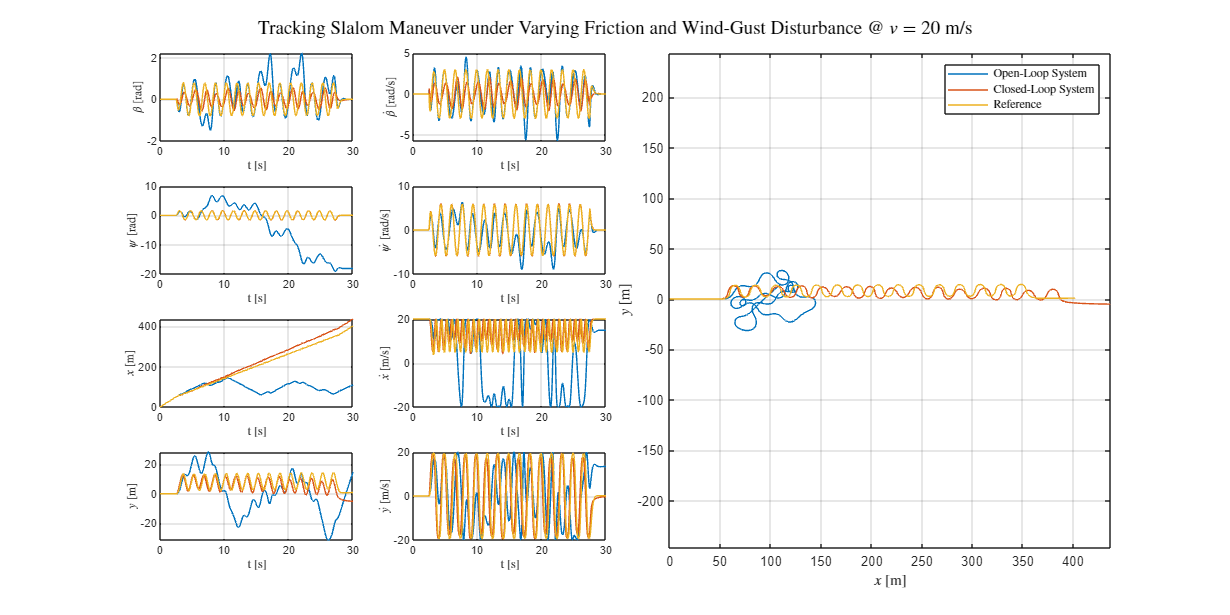

% Reference states (LC = lane-change, SP = skidpad, FH = fishhook, SL = slalom)
BETA_REF = BETA_SL(5,:);
BETA_DOT_REF = BETA_DOT_SL(5,:);
PSI_REF = PSI_SL(5,:);
PSI_DOT_REF = PSI_DOT_SL(5,:);
PX_REF = PX_SL(5,:);
VX_REF = VX_SL(5,:);
PY_REF = PY_SL(5,:);
VY_REF = VY_SL(5,:);
DELTA_REF = u_slalom;

% Simulate open-loop system with varying friction and disturbance

% Initialization
dt = 0.001; % Simulation timestep [s]
v = 0.35; % Vehicle velocity [m/s]
X = [];
X(:,1) = [0;0];
X_dot = [];
Psi = [];
Psi(1) = 0;
Beta = [];
Vx = [];
Vy = [];
Px = [];
Px(1) = 0;
Py = [];
Py(1) = 0;

% Simulation at each millisecond
for t=1:30000
    system_ol = psinfo(S_ol, 'eval', [u1_signal(t) u2_signal(t) u3_signal(t) u4_signal(t)]);
    [A_ol, B_ol, C_ol, D_ol] = ltiss(system_ol);
    X_dot(:,t) = A_ol*X(:,t) + B_ol*[(w_signal(:,t).*cos(Psi(t))); DELTA_REF(:,t)];
    X(:,t+1) = X(:,t) + X_dot(:,t)*dt;
    Beta(t) = X(1,t);
    Psi(t+1) = Psi(t) + X(2,t)*dt;
    Vx(t) = v*cos(Psi(t) + Beta(t));
    Vy(t) = v*sin(Psi(t) + Beta(t));
    Px(t+1) = Px(t) + Vx(t)*dt;
    Py(t+1) = Py(t) + Vy(t)*dt;
end
BETA_OL = Beta;
BETA_DOT_OL = X_dot(1,:);
PSI_OL = Psi;
PSI_DOT_OL = X(2,:);
PX_OL = Px;
VX_OL = Vx;
PY_OL = Py;
VY_OL = Vy;

% Simulate closed-loop system with varying friction and disturbance

% Initialization
dt = 0.001; % Simulation timestep [s]
v = 0.35; % Vehicle velocity [m/s]
X = [];
X(:,1) = [0;0];
X_dot = [];
Psi = [];
Psi(1) = 0;
Beta = [];
Vx = [];
Vy = [];
Px = [];
Px(1) = 0;
Py = [];
Py(1) = 0;

% Simulation at each millisecond
for t=1:30000
    system_cl = psinfo(S_cl, 'eval', polydec(pv, [u1_signal(t) u2_signal(t) u3_signal(t) u4_signal(t)]));
    [A_cl, B_cl, C_cl, D_cl] = ltiss(system_cl);
    X_dot(:,t) = A_cl*(X(:,t) - [BETA_REF(t);PSI_DOT_REF(t)]) + B_cl*(w_signal(:,t).*cos(Psi(t)));
    X(:,t+1) = X(:,t) + X_dot(:,t)*dt;
    Beta(t) = X(1,t);
    Psi(t+1) = Psi(t) + X(2,t)*dt;
    Vx(t) = v*cos(Psi(t) + Beta(t));
    Vy(t) = v*sin(Psi(t) + Beta(t));
    Px(t+1) = Px(t) + Vx(t)*dt;
    Py(t+1) = Py(t) + Vy(t)*dt;
end
BETA_CL = Beta;
BETA_DOT_CL = X_dot(1,:);
PSI_CL = Psi;
PSI_DOT_CL = X(2,:);
PX_CL = Px;
VX_CL = Vx;
PY_CL = Py;
VY_CL = Vy;

% Plot
t=1:30000;
fig = figure(); 
fig.Position(3:4) = [1500, 750];
% Plot states
subplot(4,4,1)
plot(t/1000,BETA_OL(:,1:end)')
hold on
plot(t/1000,BETA_CL(:,1:end)')
plot(t/1000,BETA_REF(:,1:end)')
xlabel('t [s]','Interpreter','latex')
ylabel('$\beta$ [rad]','Interpreter','latex')
grid('on')
subplot(4,4,2)
plot(t/1000,BETA_DOT_OL(:,1:end)')
hold on
plot(t/1000,BETA_DOT_CL(:,1:end)')
plot(t/1000,BETA_DOT_REF(:,1:end)')
xlabel('t [s]','Interpreter','latex')
ylabel('$\dot{\beta}$ [rad/s]','Interpreter','latex')
grid('on')
subplot(4,4,5)
plot(t/1000,PSI_OL(:,1:end-1)')
hold on
plot(t/1000,PSI_CL(:,1:end-1)')
plot(t/1000,PSI_REF(:,1:end-1)')
xlabel('t [s]','Interpreter','latex')
ylabel('$\psi$ [rad]','Interpreter','latex')
grid('on')
subplot(4,4,6)
plot(t/1000,PSI_DOT_OL(:,1:end-1)')
hold on
plot(t/1000,PSI_DOT_CL(:,1:end-1)')
plot(t/1000,PSI_DOT_REF(:,1:end-1)')
xlabel('t [s]','Interpreter','latex')
ylabel('$\dot{\psi}$ [rad/s]','Interpreter','latex')
grid('on')
subplot(4,4,9)
plot(t/1000,PX_OL(:,1:end-1)')
hold on
plot(t/1000,PX_CL(:,1:end-1)')
plot(t/1000,PX_REF(:,1:end-1)')
xlabel('t [s]','Interpreter','latex')
ylabel('$x$ [m]','Interpreter','latex')
grid('on')
subplot(4,4,10)
plot(t/1000,VX_OL(:,1:end)')
hold on
plot(t/1000,VX_CL(:,1:end)')
plot(t/1000,VX_REF(:,1:end)')
xlabel('t [s]','Interpreter','latex')
ylabel('$\dot{x}$ [m/s]','Interpreter','latex')
grid('on')
subplot(4,4,13)
plot(t/1000,PY_OL(:,1:end-1)')
hold on
plot(t/1000,PY_CL(:,1:end-1)')
plot(t/1000,PY_REF(:,1:end-1)')
xlabel('t [s]','Interpreter','latex')
ylabel('$y$ [m]','Interpreter','latex')
grid('on')
subplot(4,4,14)
plot(t/1000,VY_OL(:,1:end)')
hold on
plot(t/1000,VY_CL(:,1:end)')
plot(t/1000,VY_REF(:,1:end)')
xlabel('t [s]','Interpreter','latex')
ylabel('$\dot{y}$ [m/s]','Interpreter','latex')
grid('on')
% Plot trajectory
subplot(4,4,[3,4,7,8,11,12,15,16])
plot(PX_OL(:,1:end-1)',PY_OL(:,1:end-1)')
hold on
plot(PX_CL(:,1:end-1)',PY_CL(:,1:end-1)')
plot(PX_REF(:,1:end-1)',PY_REF(:,1:end-1)')
xlabel('$x$ [m]','Interpreter','latex')
ylabel('$y$ [m]','Interpreter','latex')
axis equal
grid('on')
% Common title and legend
sgtitle('Tracking Slalom Maneuver under Varying Friction and Wind-Gust Disturbance @ $v = 0.35$ m/s','Interpreter','latex')
legend('Open-Loop System', 'Closed-Loop System', 'Reference', ...
       'Interpreter','latex','Location','northeast')